# Design of a Controller for an Unstable System

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

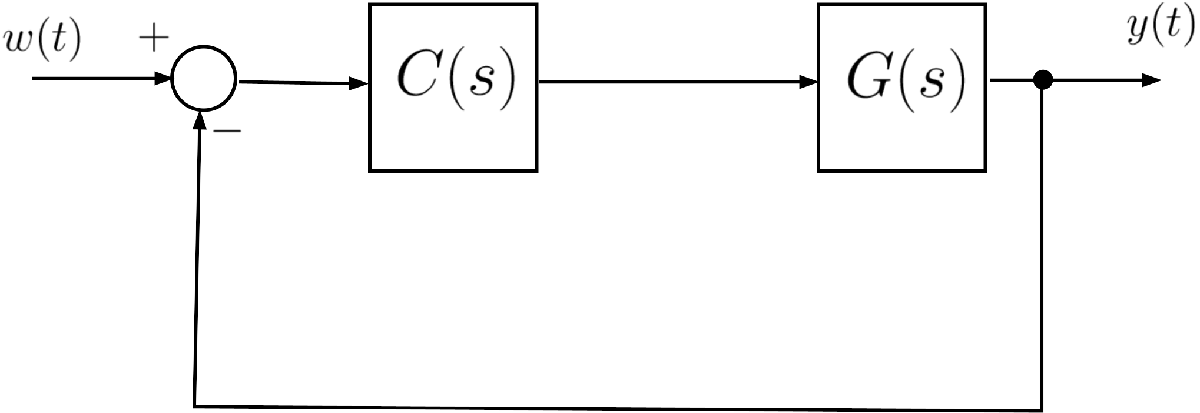	

where $G(s)$ is given by                


$$G(s) = \frac{1+2s}{(1-s)\,(1+10\,s)}$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- The crossover angular frequency satisfies $\omega_c \ge 10\;\text{rad/s}$; 

- The phase margin satisfies $\varphi_m \ge 60^{\degree}$.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Since the system is open-loop unstable, the Bode stability criterion cannot be used in the way that is usual for the loop-shaping approach to the design of the controller for minimum-phase systems. Hence, as suggested in Example 3 in slides 41-44 of Part 10 of the lecture handouts, we use a **dual-loop control scheme**, as shown in the Figure below 

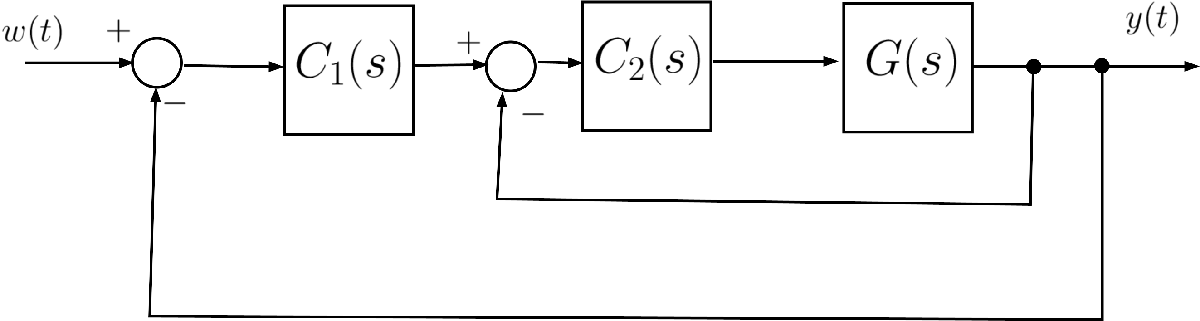

The design of the controller $C(s)$ is carried out by the following logical steps:

- The controller $C_2(s)$ is designed so as the **inner-loop transfer function **$F_2(s)$ from the output of the block $C_1(s)$ is **asymptotically** **stable**.

-  Subsequently, $C_1(s)$ will be designed to meet the other requirements.

### A1: Answer to Question Q1

#### Design of the Inner Loop Controller

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = (1+2*s)/((1-s)*(1+10*s)); % the unstable process G(s)

**First Trial**: To design the inner asymptotically-stable loop, the first attempt is to set


$$C_2(s) = \mu_2,\; \mu_2 \in \mathbb{R}$$


**First Approach**: Apply the **Routh-Hurwitz criterion.**


$$C_2(s) = \mu_2 \; \Longrightarrow \; L_2(s) = \mu_2\,\frac{(1+2s)}{(1-s)\,(1+10s)} \; \Longrightarrow \; 1+L_2(s)=0 \,\longleftrightarrow\,
-10s^2+\left(9+2\,\mu_2\right)s+(\mu_2+1) =0
$$


Thus, we obtain the following conditions:

- if $\mu_2<-\frac{9}{2}$ then the inner loop is asymptotically stable;

- if $\mu_2 \in \left(-\frac{19}{2}-\sqrt{60}\;,\quad -\frac{9}{2}\right)$, the closed-loop poles are complex conjugate;

- if $\mu_2 < -\frac{19}{2}-\sqrt{60}$, the closed-loop poles are real and distinct.

All values $\mu_2<-\frac{9}{2}$ are feasible and the goal here is merely to stabilise the open-loo unstable system to be controlled. In this respect, a possible attempt is to set $\mu_2=-10$.

**Hint**: What if $\mu _2 = -30$ or $\mu_2 = -300$? Complete the design of the controller $C_1(s)$according to the proposed design procedure and compare the findings with the actual proposed solution.	

**Second Approach**: Apply the **Nyquist Stability Criterion**. 

Let's explore the Nyquist diagram of the frequency response $L_2(j\omega)$, varying the gain constant $\mu_2$. 

**Note**: we have to obtain the same result as before, when we used the Routh-Hurwitz criterion.

- **First scenario**: explore the Nyquist diagram when $\mu_2>0$

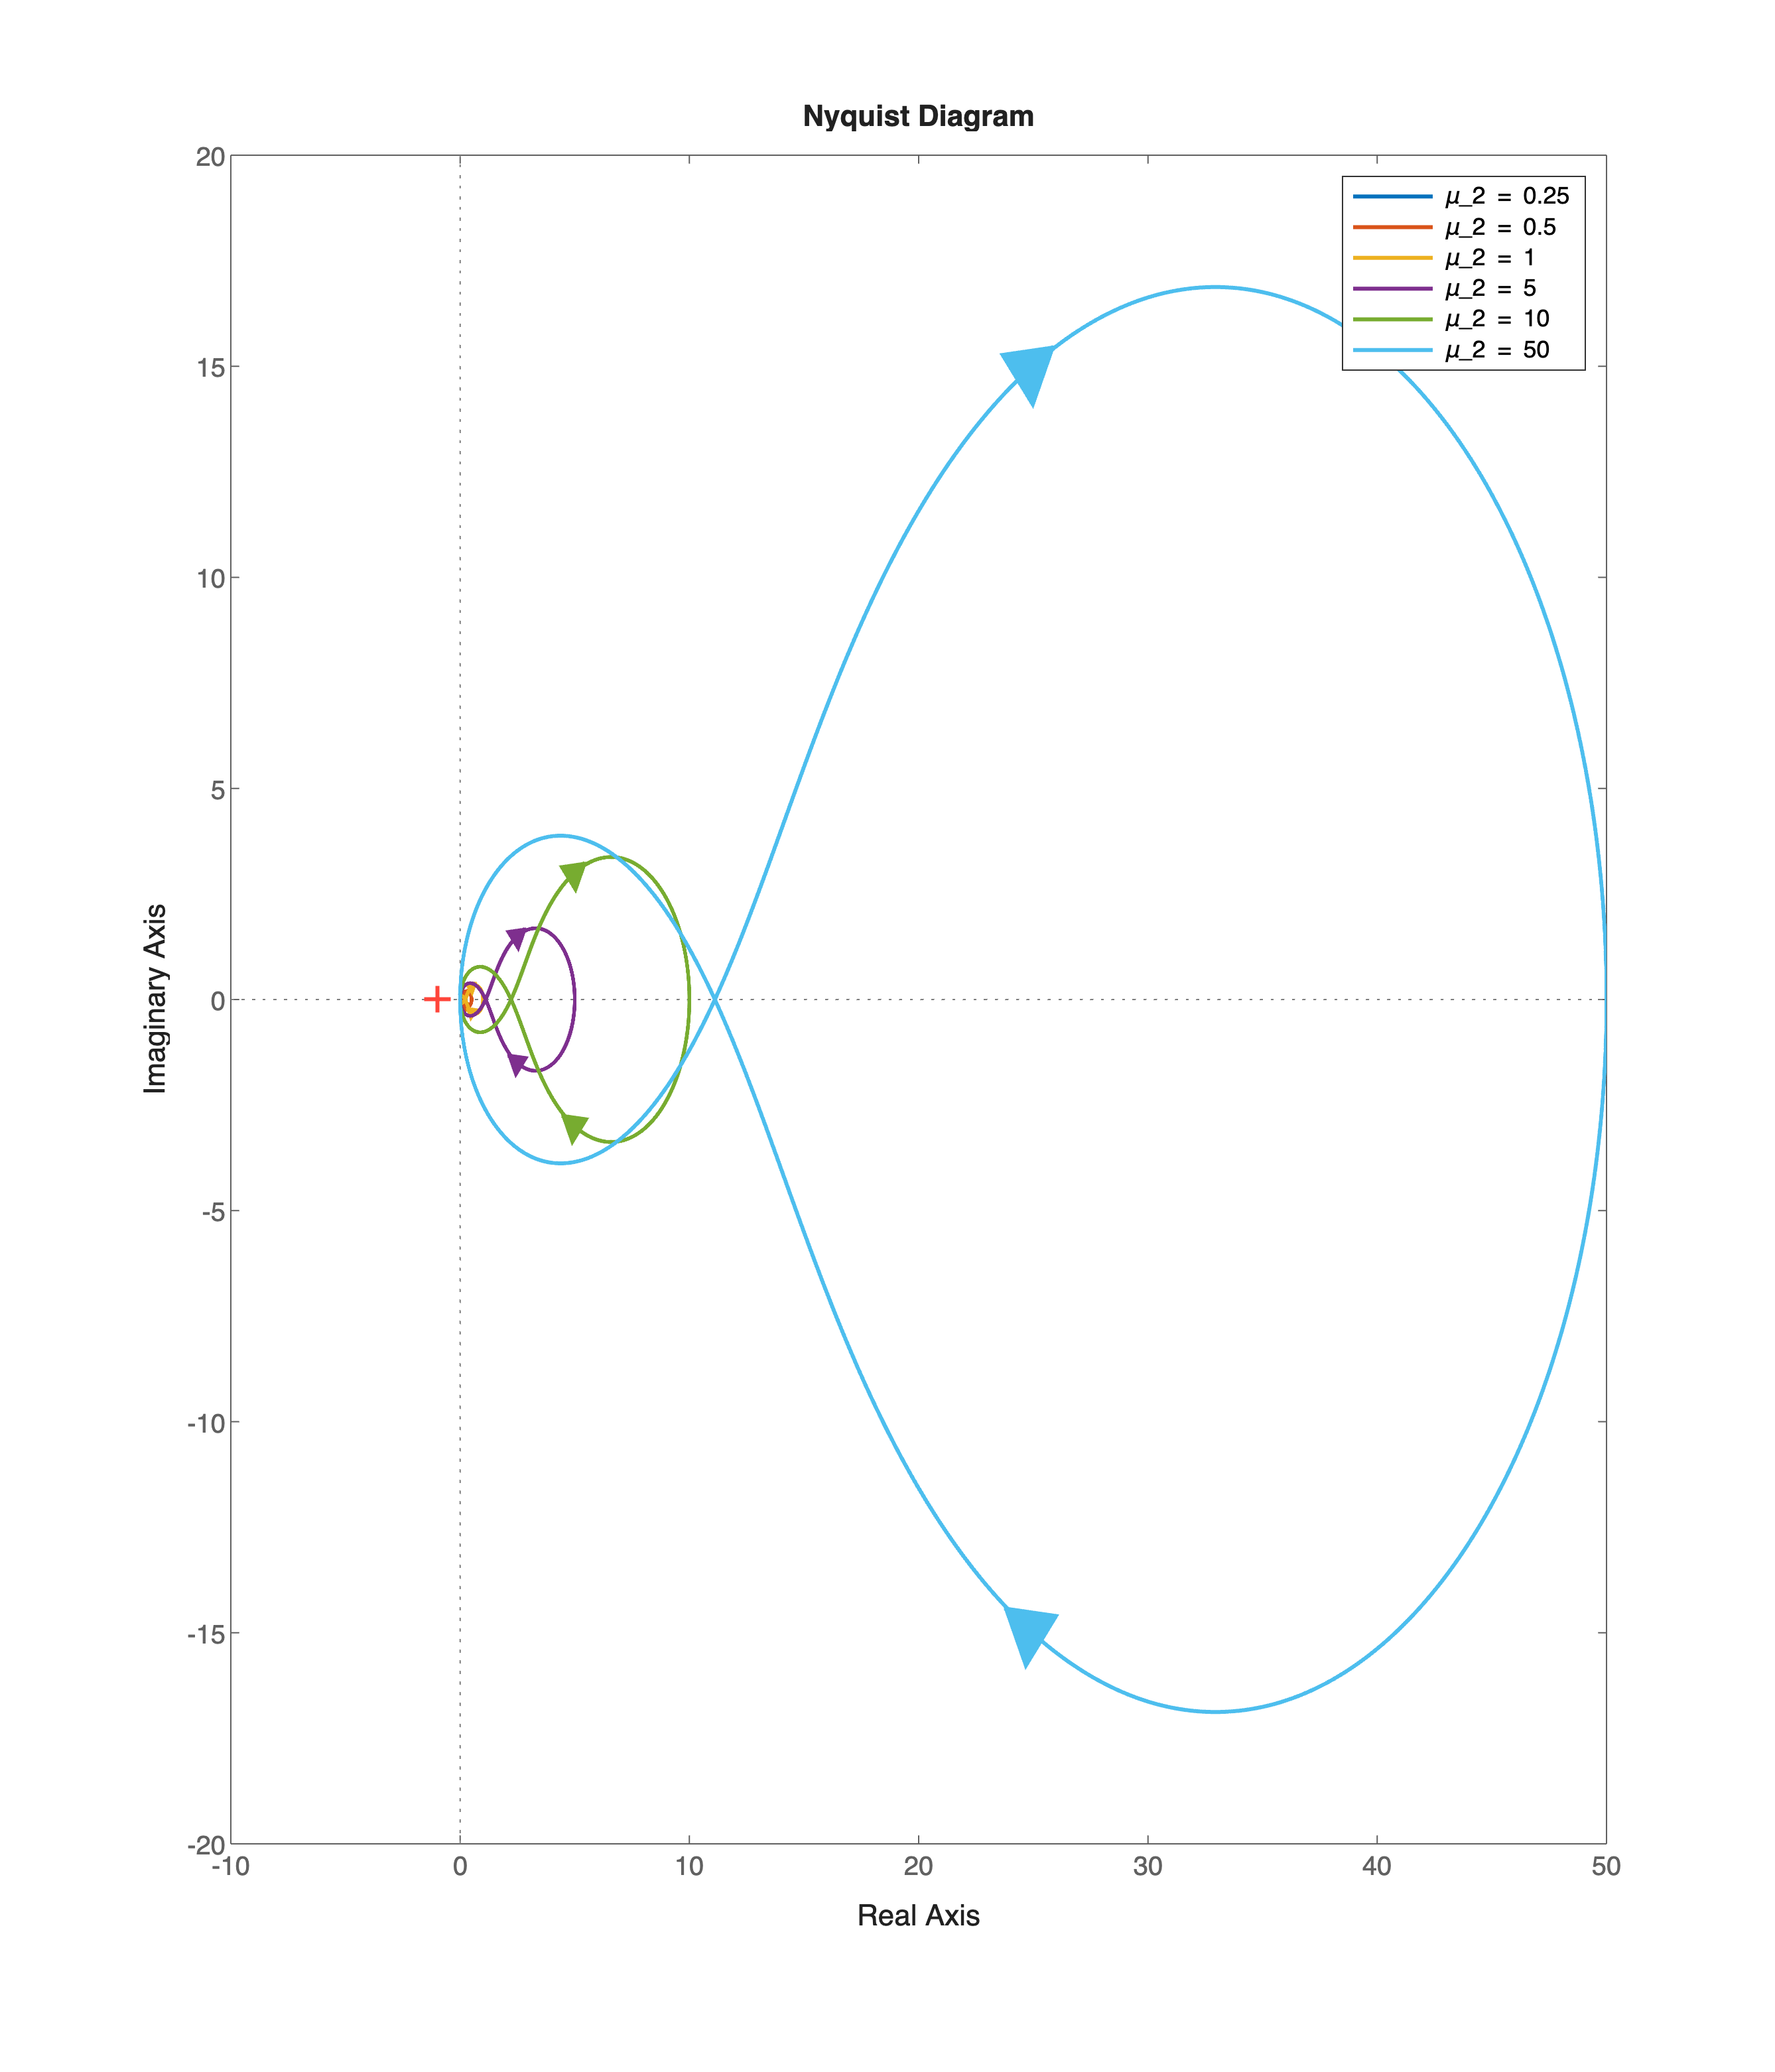

mu2SET = [0.25, 0.5, 1, 5, 10, 50];
L2s_SET = cell(numel(mu2SET),1);

% let's plot the Nyquist diagrams, varying the gain mu_2
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

mu2VAL = mu2SET(1);
L2s_SET{1} = mu2VAL*Gs;

L2s_SET{1}.Name = ['\mu_2 = ', num2str(mu2SET(1)),' '];

np = nyquistplot(ax, L2s_SET{1}, omVALS); 
% -------------
% refer to "NyquistDiagrams_characteristicFeatures.mlx" in Part 09
% -------------
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

for n = 2: numel(mu2SET)
    mu2VAL = mu2SET(n);
    L2s_SET{n} = mu2VAL*Gs;
    addResponse(np, L2s_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    np.Responses(n).Name = ['\mu_2 = ', num2str(mu2SET(n), 3),' '];
    np.Responses(n).LineWidth = 1.5;
end % for n

Let's put in evidence the region around the point $-1+j0$:

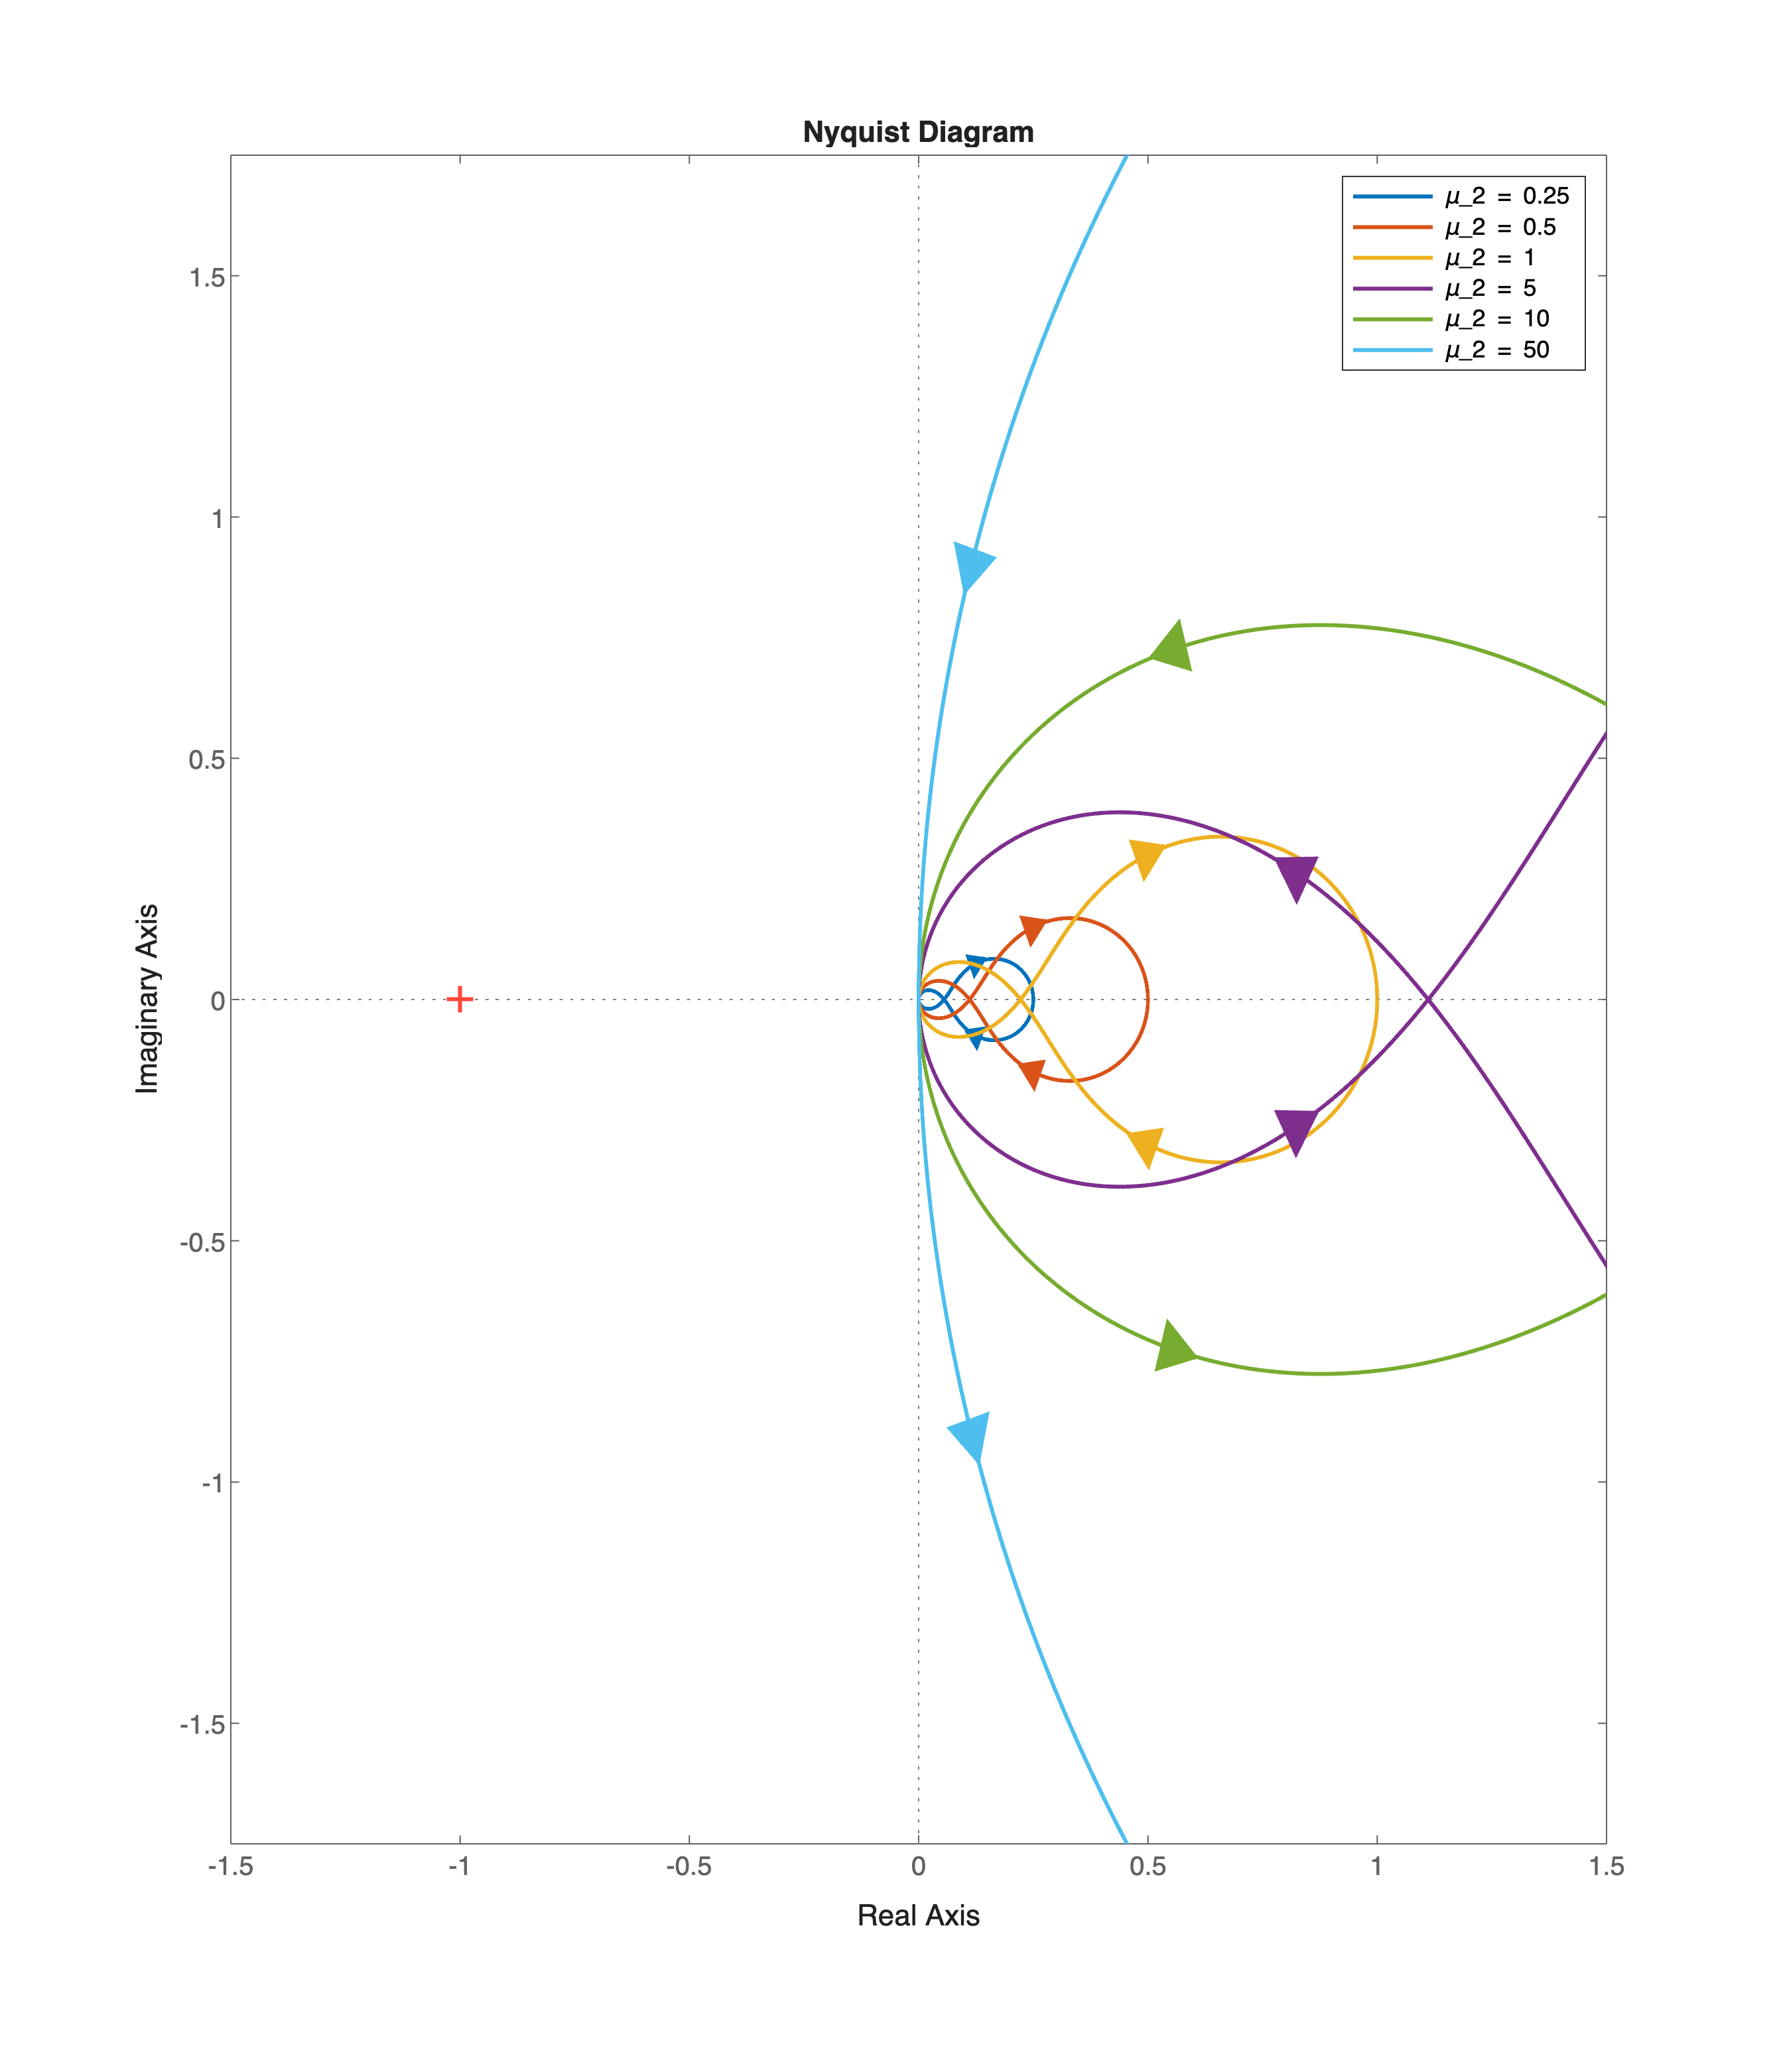


% let's plot the Nyquist diagrams, varying the gain mu_2
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

mu2VAL = mu2SET(1);
L2s_SET{1} = mu2VAL*Gs;

L2s_SET{1}.Name = ['\mu_2 = ', num2str(mu2SET(1)),' '];

np = nyquistplot(ax, L2s_SET{1}, omVALS); 
% -------------
% refer to "NyquistDiagrams_characteristicFeatures.mlx" in Part 09
% -------------
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

for n = 2: numel(mu2SET)
    mu2VAL = mu2SET(n);
    L2s_SET{n} = mu2VAL*Gs;
    addResponse(np, L2s_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    np.Responses(n).Name = ['\mu_2 = ', num2str(mu2SET(n), 3),' '];
    np.Responses(n).LineWidth = 1.5;
end % for n

np.XLimits = [-1.5, 1.5];
np.YLimits = [-1.75, +1.75];

**Note: **the point $-1+j0$ is always **outside** the Nyquist diagram $\Gamma$. There is no possibility to stabilise the system using a positive gain $\mu_2$: the number of open-loop unstable poles is $n_{p>0} = +1$, whereas the number $N$ of **counterclockwise** rotations of $\Gamma$ around the point $(-1,\,0)$ is $N=0$. Thus, $N \neq n_{p>0}\;\forall \mu_2>0$. 

The **closed-loop system** is **always** **unstable** when $\mathbf \mu_2>0$.

- **Second scenario**: explore the Nyquist diagram when $\mu_2 < 0$

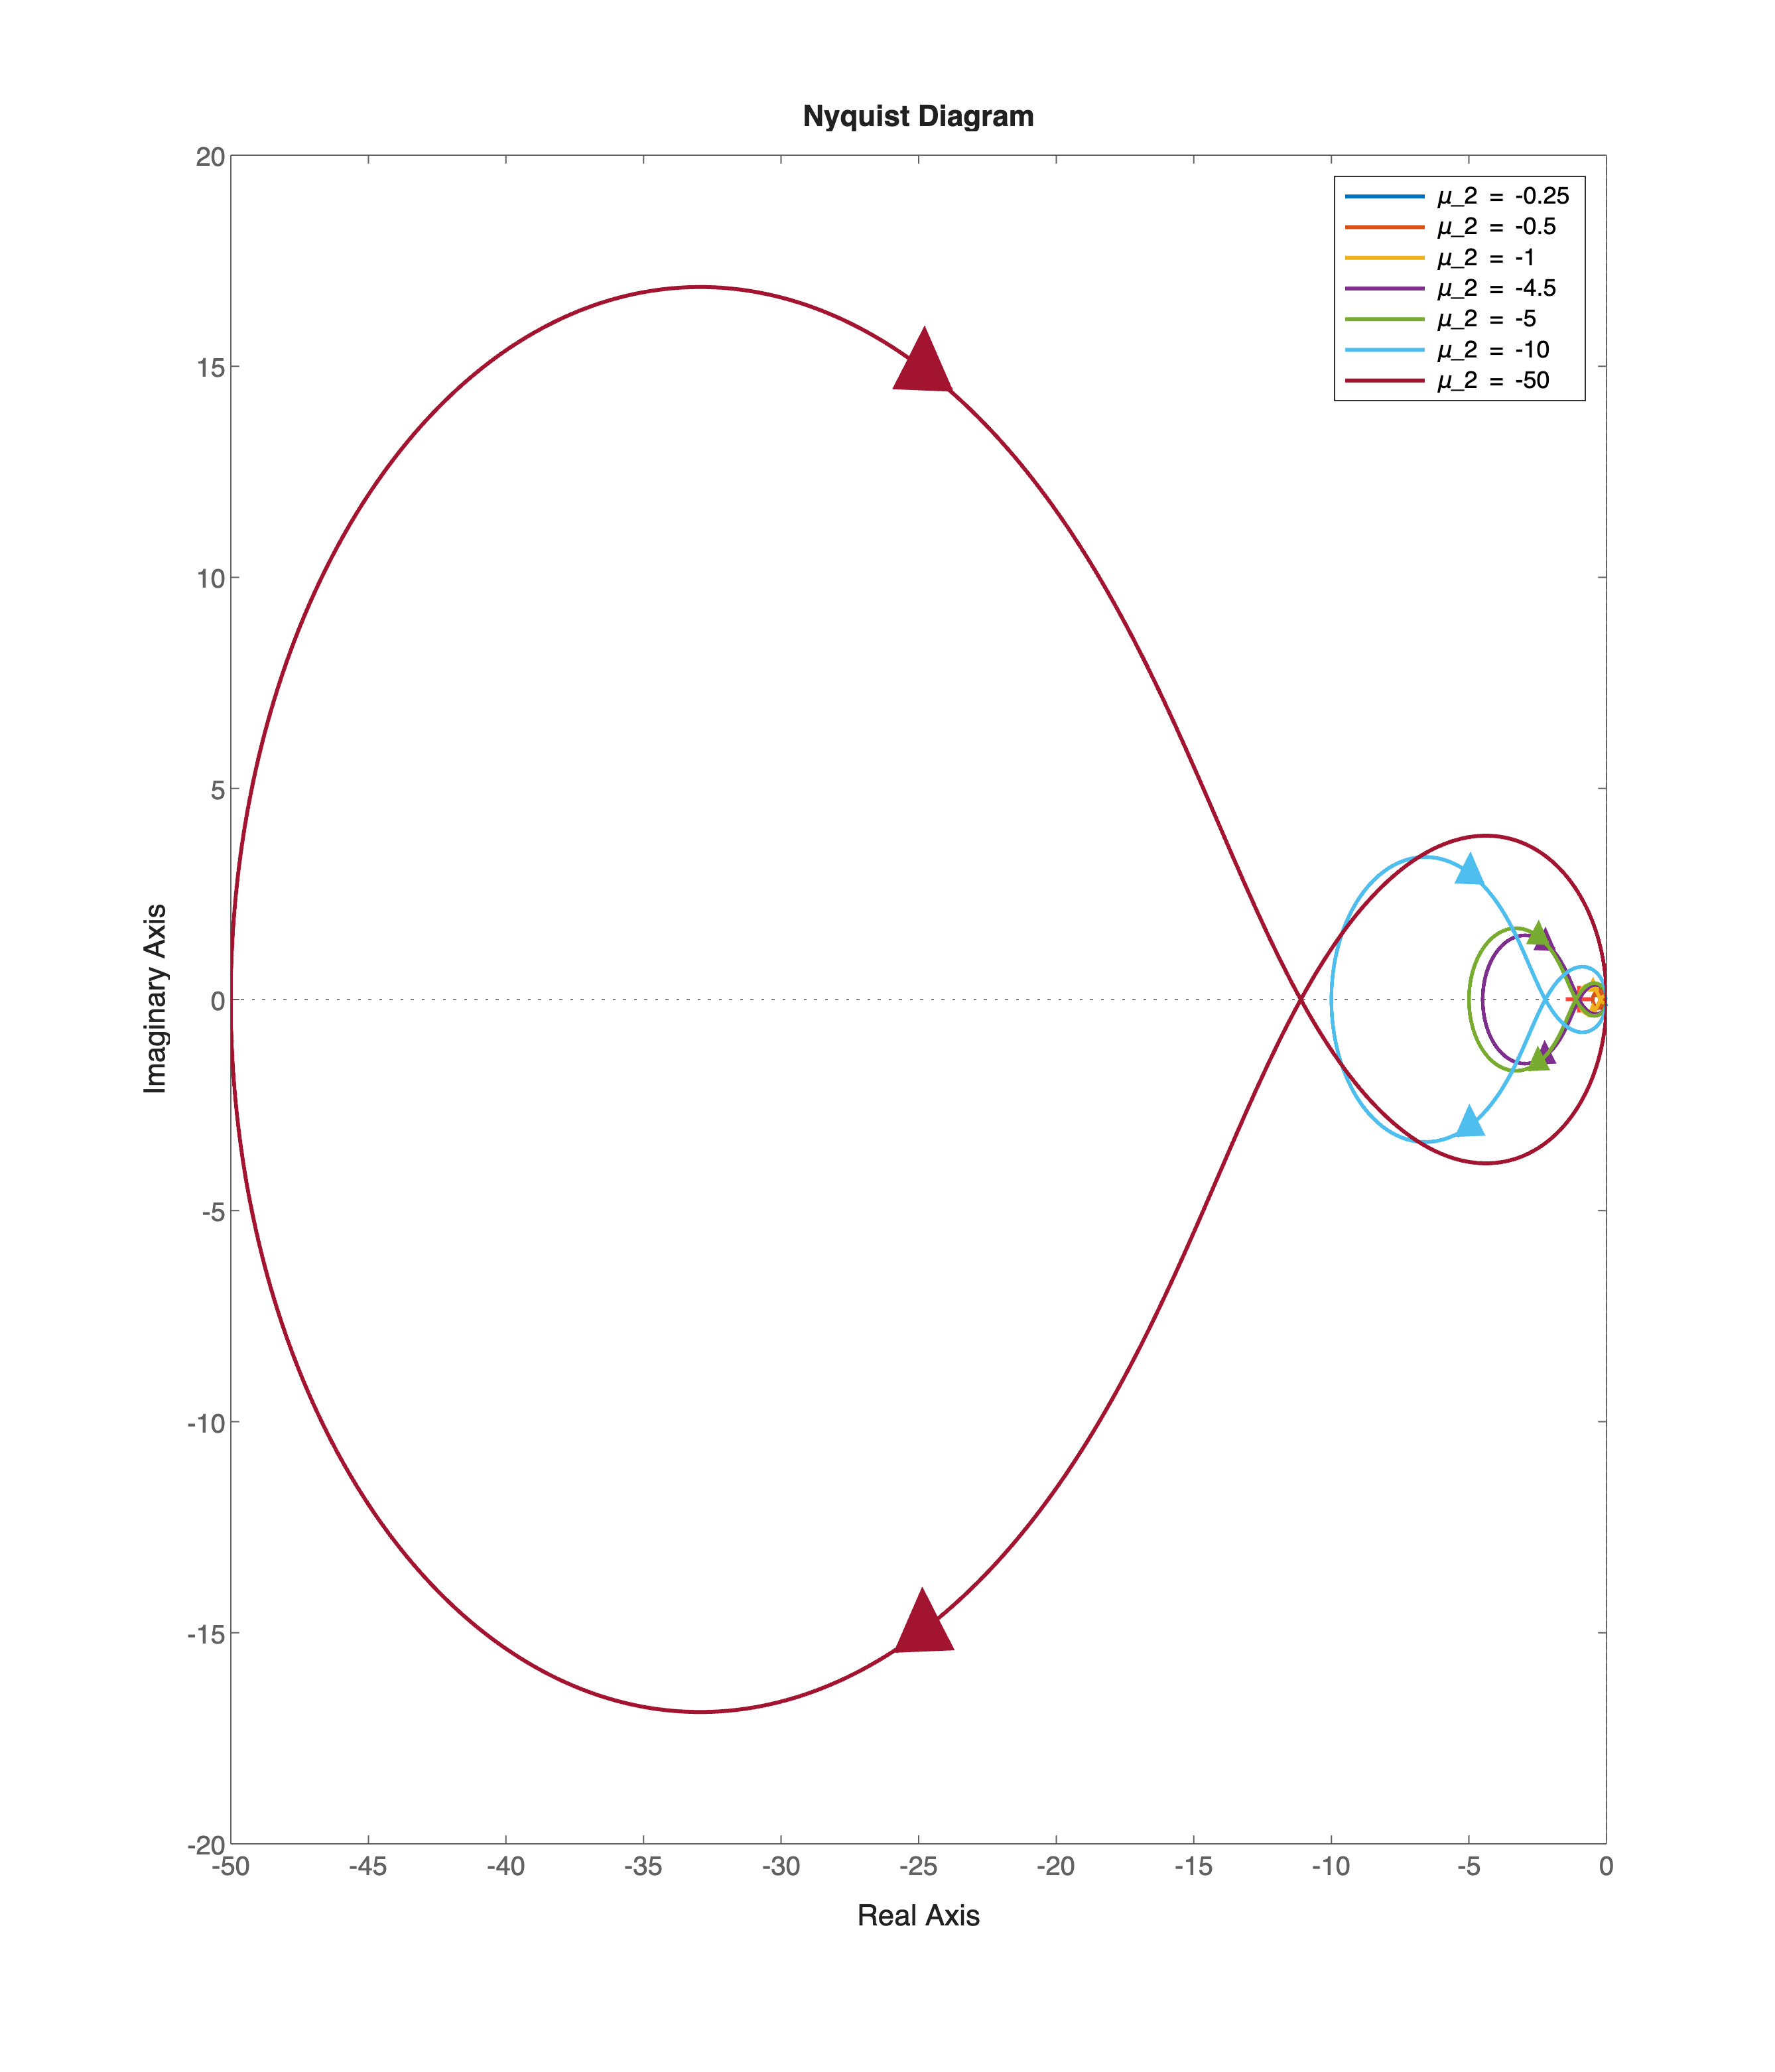

mu2SET = (-1).*[0.25, 0.5, 1, 4.5,  5, 10, 50]; % negative gain values
% NOTE: we use the critical gain value obtained applying the Routh-Hurwitz
% criterion (i.e -9/2)
L2s_SET = cell(numel(mu2SET),1);

% let's plot the Nyquist diagrams, varying the gain mu_2
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

mu2VAL = mu2SET(1);
L2s_SET{1} = mu2VAL*Gs;

L2s_SET{1}.Name = ['\mu_2 = ', num2str(mu2SET(1)),' '];

np = nyquistplot(ax, L2s_SET{1}, omVALS); 
% -------------
% refer to "NyquistDiagrams_characteristicFeatures.mlx" in Part 09
% -------------
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

for n = 2: numel(mu2SET)
    mu2VAL = mu2SET(n);
    L2s_SET{n} = mu2VAL*Gs;
    addResponse(np, L2s_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    np.Responses(n).Name = ['\mu_2 = ', num2str(mu2SET(n), 3),' '];
    np.Responses(n).LineWidth = 1.5;
end % for n

Let's put in evidence the region around the point $-1+j0$:

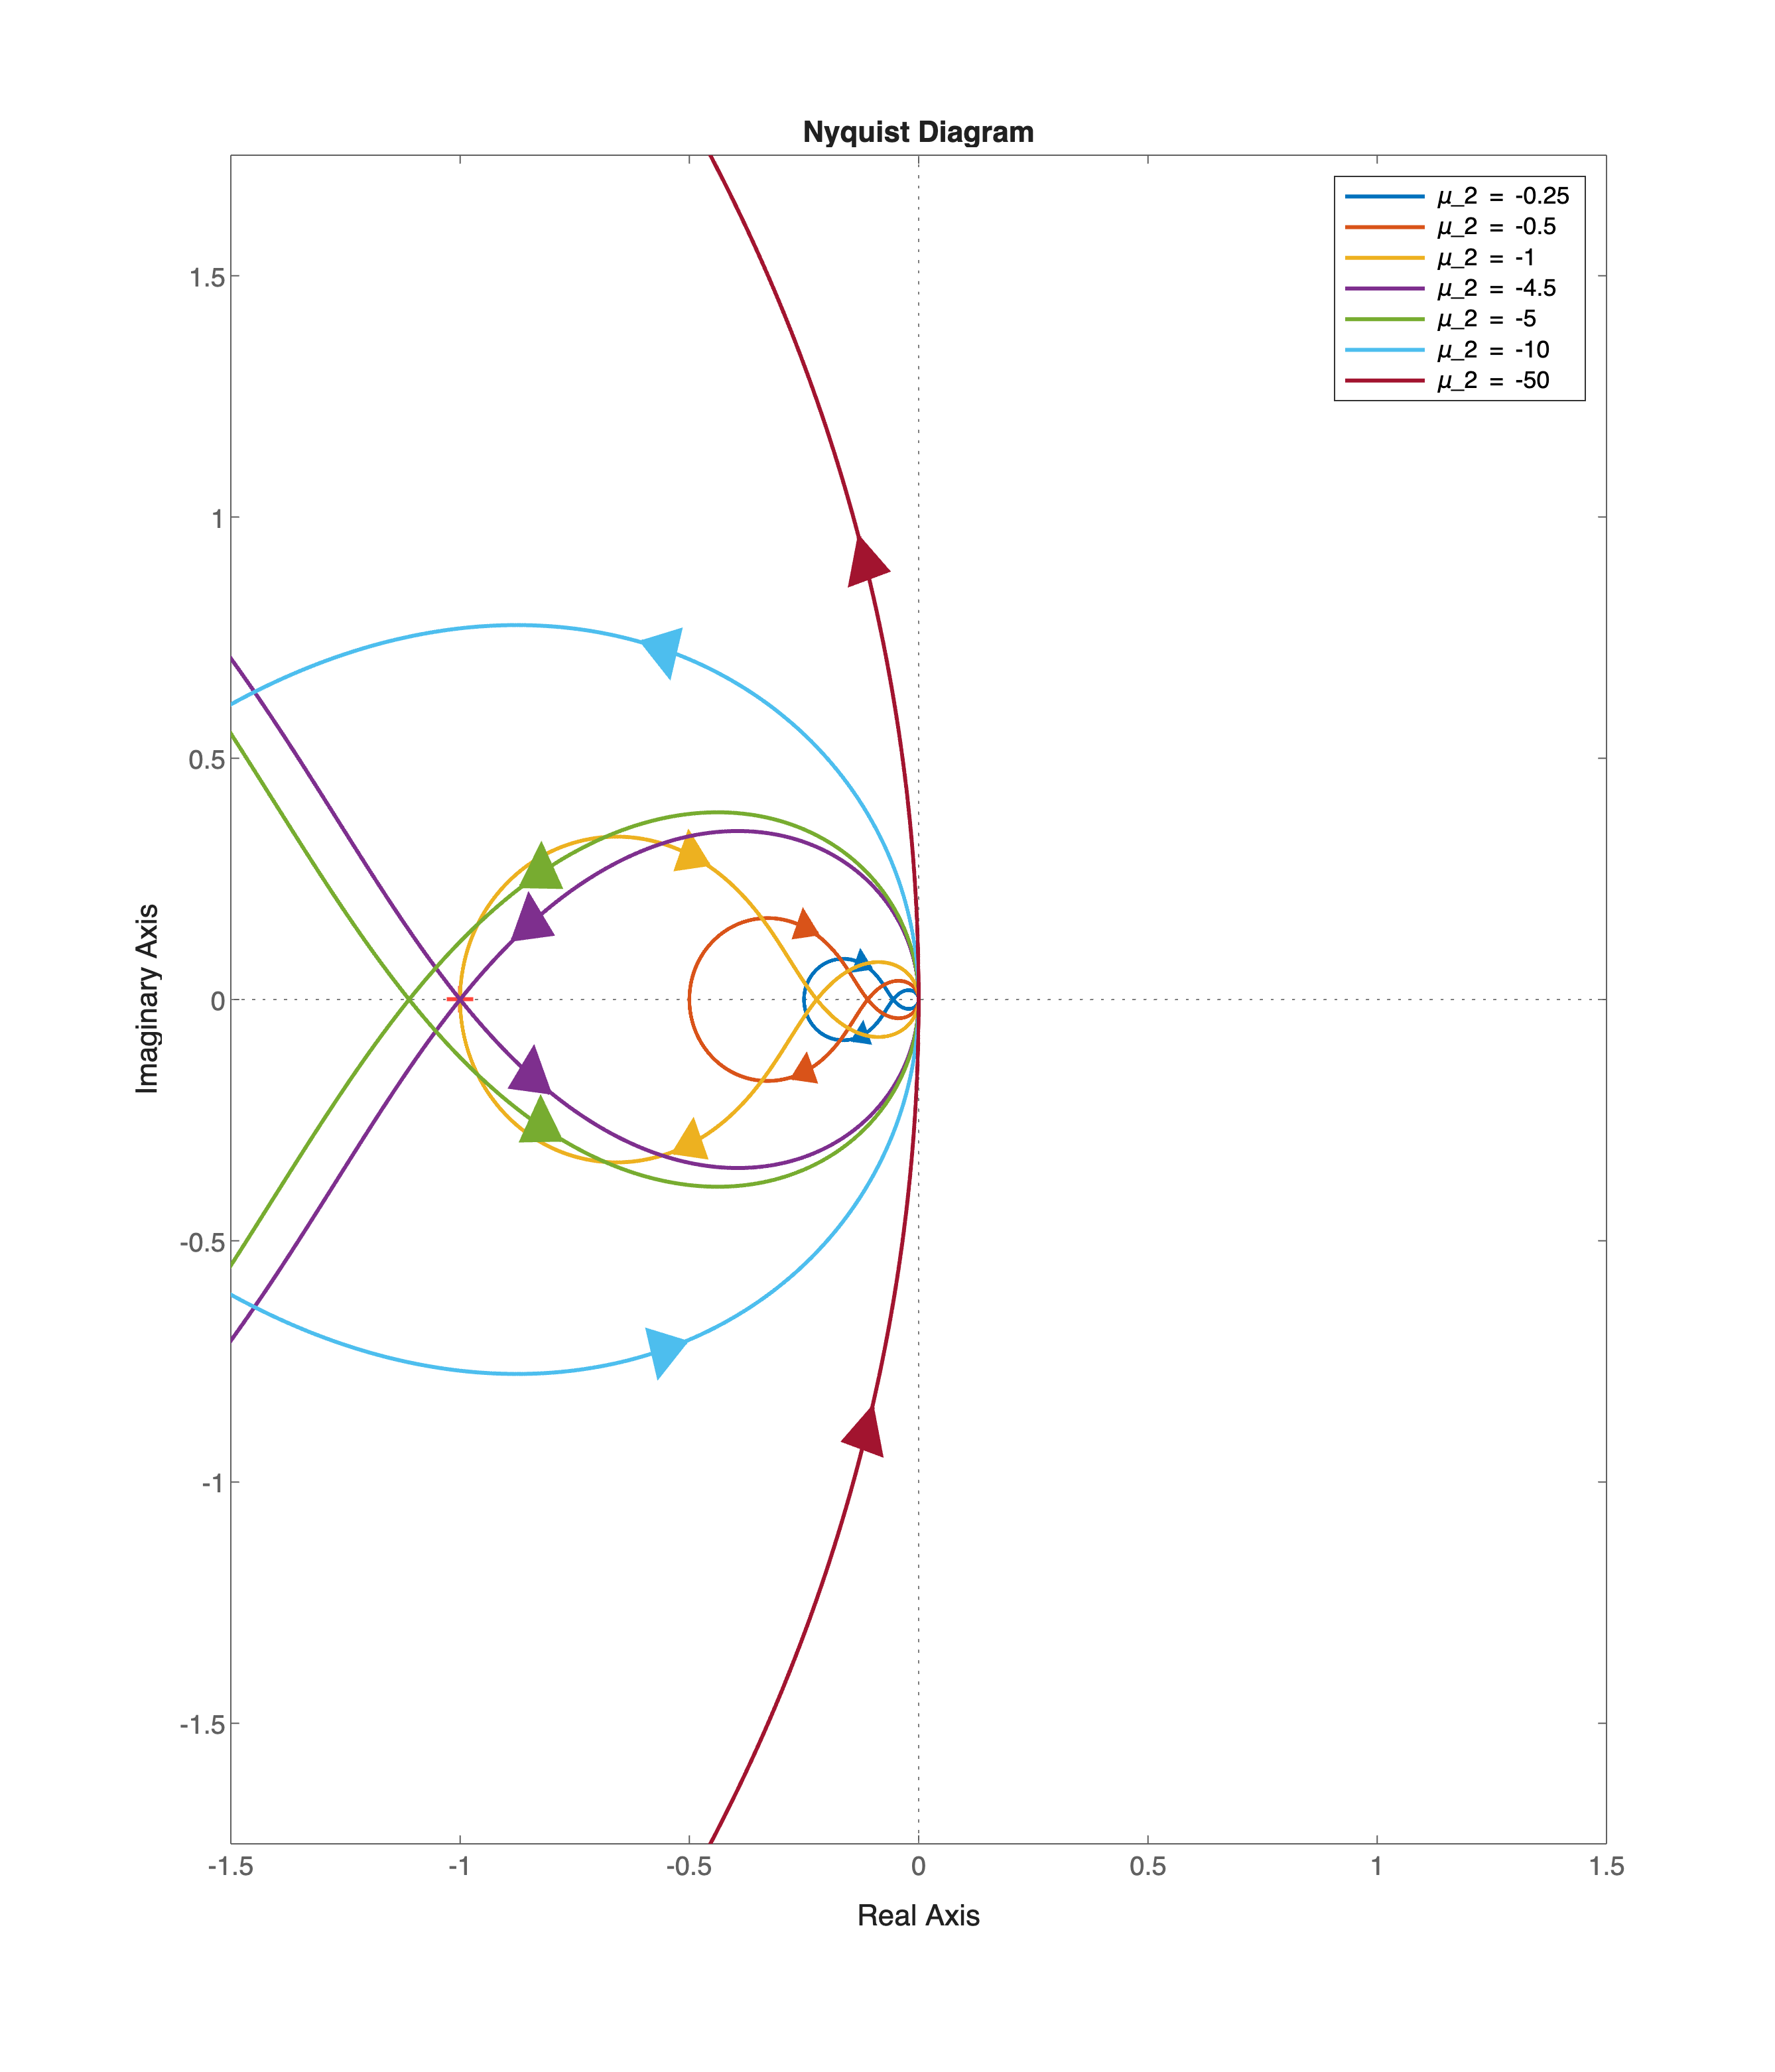

mu2SET = (-1).*[0.25, 0.5, 1, 4.5,  5, 10, 50]; % negative gain values
% NOTE: we use the critical gain value obtained applying the Routh-Hurwitz
% criterion (i.e -9/2)
L2s_SET = cell(numel(mu2SET),1);

% let's plot the Nyquist diagrams, varying the gain mu_2
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

mu2VAL = mu2SET(1);
L2s_SET{1} = mu2VAL*Gs;

L2s_SET{1}.Name = ['\mu_2 = ', num2str(mu2SET(1)),' '];

np = nyquistplot(ax, L2s_SET{1}, omVALS); 
% -------------
% refer to "NyquistDiagrams_characteristicFeatures.mlx" in Part 09
% -------------
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

for n = 2: numel(mu2SET)
    mu2VAL = mu2SET(n);
    L2s_SET{n} = mu2VAL*Gs;
    addResponse(np, L2s_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    np.Responses(n).Name = ['\mu_2 = ', num2str(mu2SET(n), 3),' '];
    np.Responses(n).LineWidth = 1.5;
end % for n

np.XLimits = [-1.5, 1.5];
np.YLimits = [-1.75, +1.75];

**Note:** when $\mu_2<0$, the closed-loop system can be stabilised. In fact

- When $\mu_2>-\frac{9}{2}$, then $N=0$, but $n_{p>0} = +1$; thus $N \neq n_{p>0}$ in this scenario.

- When $\mu_2<-\frac{9}{2}$, then $N=+1$ and $n_{p>0} = +1$. Given $N=n_{p>0}$, the closed-loop system is asymptotically stable.

- How to find the critical gain value $\bar \mu_2 = -\frac{9}{2}$? The most efficient way is exploiting the Routh-Hurwitz criterion.

**Third Approach**: Analyse the **Root Locus**. 

Let's explore the Root Locus, using the `controlSystemDesigner` App:

controlSystemDesigner;

Moreover, let's select the **dual-loop control scheme** configuration in the Control System Designer.

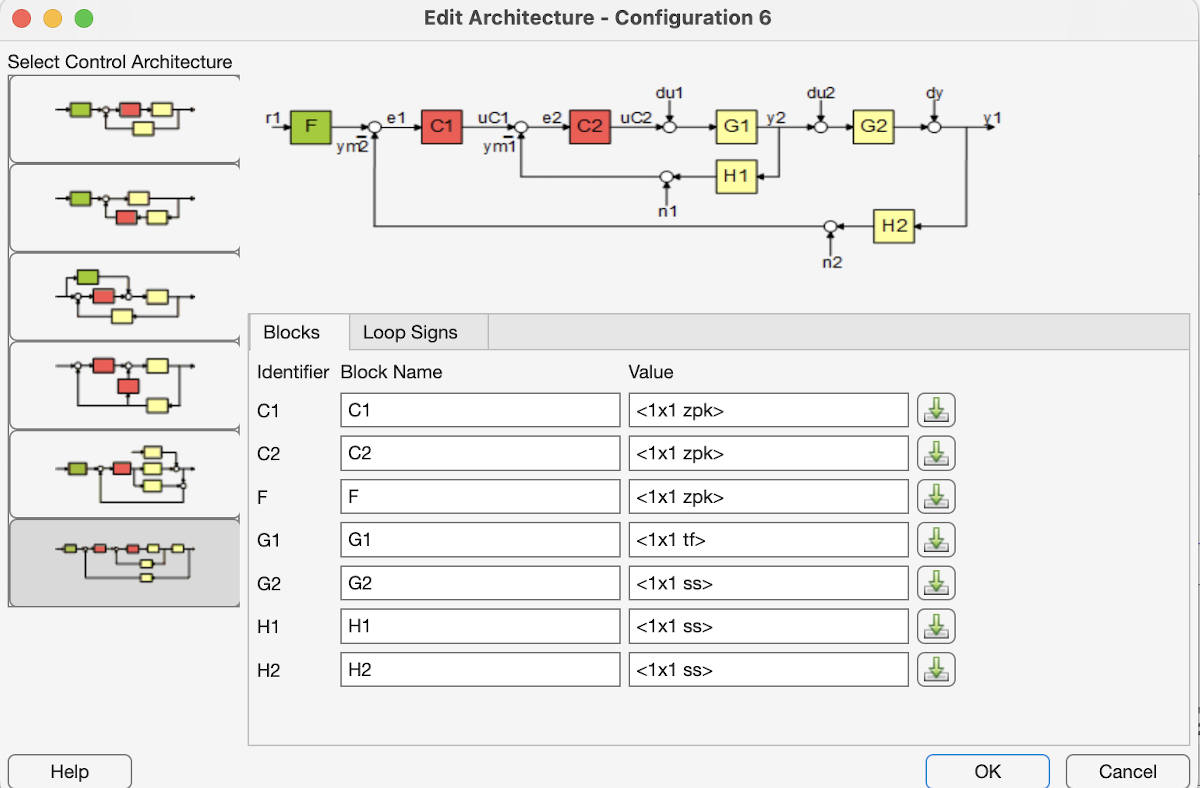

Import the `tf-object Gs` as the transfer function $G_1(s)$ in the block diagram. Let the transfer function $G_2(s)$ as is, i.e. a simple algebraic block $G_2(s) = 1$. 

**Important Remark**: Cut off the outer-loop controller, by setting $C_1(s) = 0$, when you are analysing the stability of the inner loop using the Root Locus Editor. Otherwise, you will analyse the effect of having both loops acting toghether (i.e., the outer loop interacts with the inner loop) and a useless root locus.

The resulting **root locus** is ( $C_1(s)=0$ and $C_2(s)=+1$, i.e. we are exploring every configuration with $C_2(s)=\mu_2 >0$)

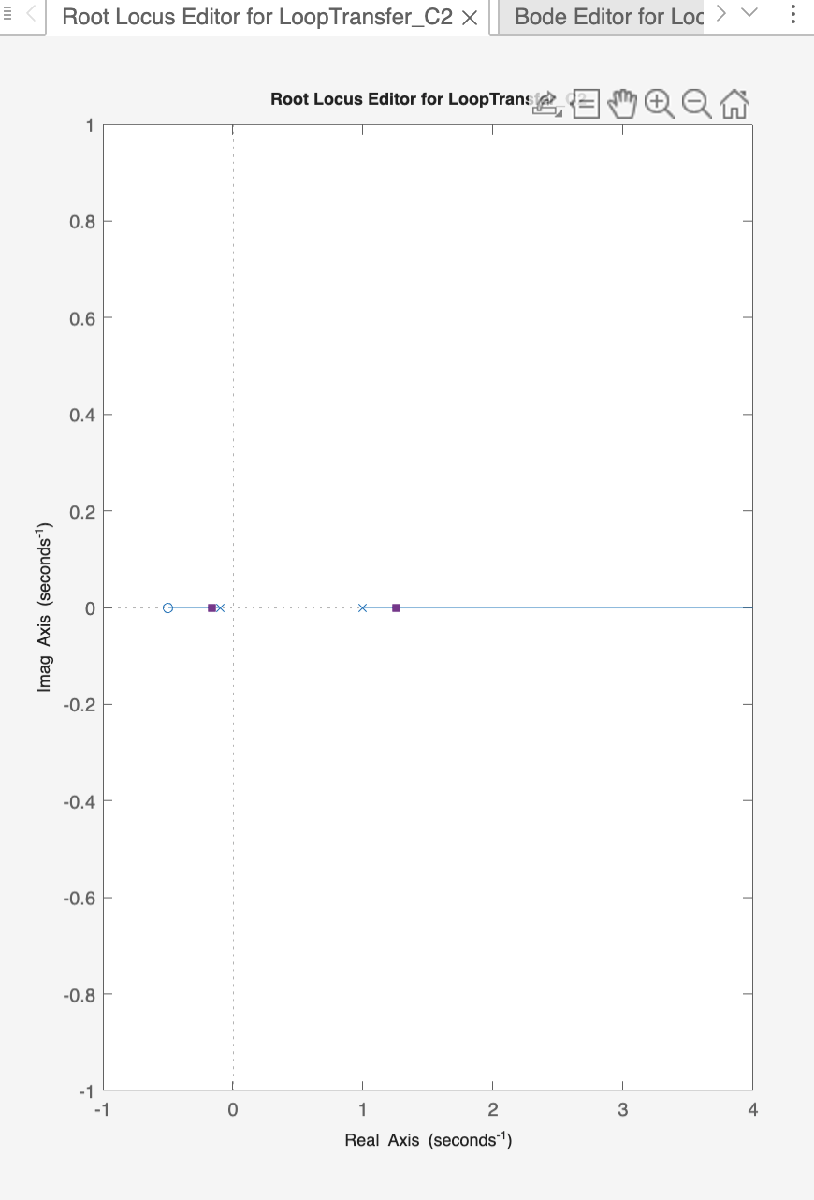

As you can notice, using $\mu_2>0$ can not stabilise the inner loop.There is a branch of the locus in the complex Right Half-Plane (RHP), thus the closed-loop **system** is **unstable** $\forall \mu_2>0$.

In details, if you consider the equation $-10s^2+\left(9+2\,\mu_2\right)s+(\mu_2+1) =0$ and if you manipulate it


$$-10s^2+\left(9+2\,\mu_2\right)s+(\mu_2+1) =0 \;
 \Longleftrightarrow \; -10\,s^2+9s+1 = -\mu_2\,\left(2s+1\right) $$


After some more manipulations, you obtain


$$\frac{2s+1}{-10s^2+9s+1} = -\frac{1}{\mu_2} \; \Longrightarrow \; \frac{\left(s+\frac{1}{2}\right)}{\left(s-1\right)\,\left(s+\frac{1}{10}\right)} = -\frac{1}{\varrho}\;,\qquad \varrho = -\frac{\mu_2}{5}$$


Thus $\mu_2>0 \Longrightarrow \varrho<0$, i.e. in the above figure we considered the Inverse Root Locus of $\frac{\left(s+\frac{1}{2}\right)}{\left(s-1\right)\,\left(s+\frac{1}{10}\right)}$

What about **negative gain** for $C_2(s)$? Simply edit the static gain of $C_2(s)$ in the Control System Designer app and change it to $\mu_2<0$ (in Figure $\mu_2=-5$)

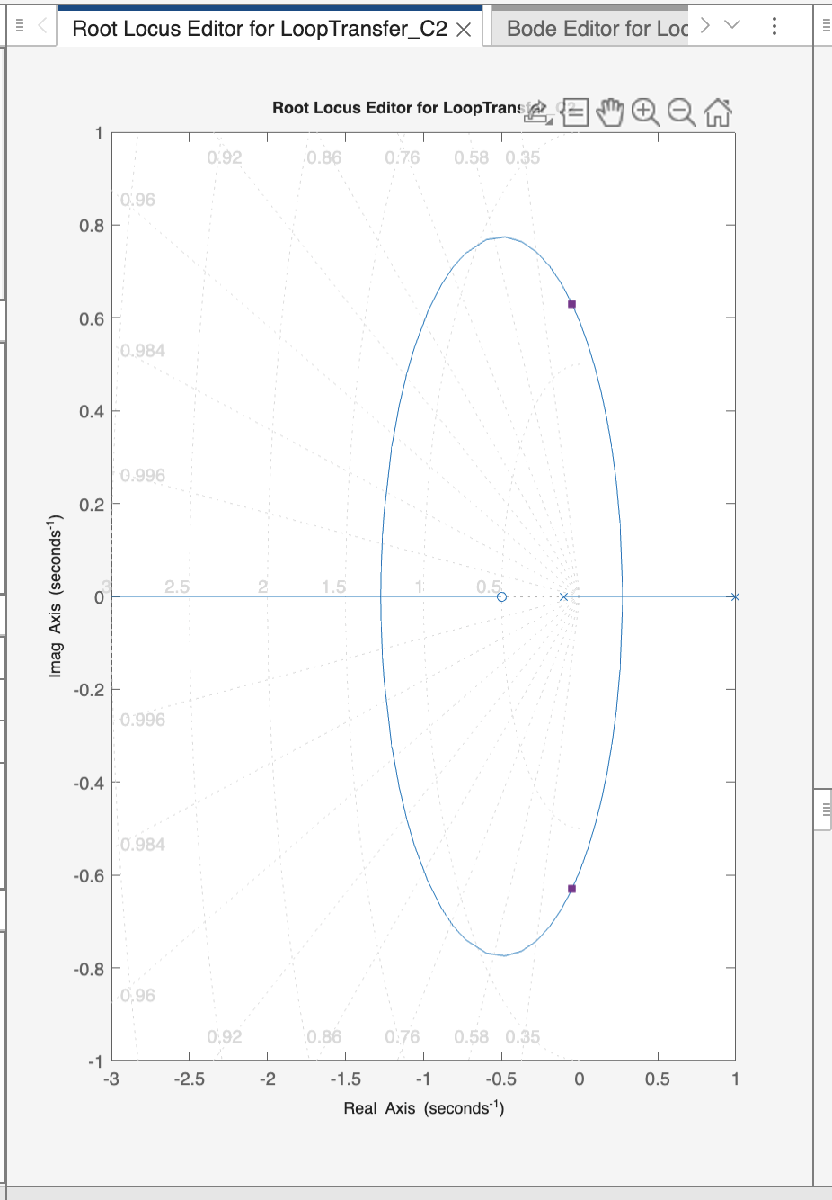

As can be seen from the figure, this time, the system is stabilised. We can tentatively choose a gain value $\mu_2$ that leads to a closed-loop system with a satisfactory frequency response. 

For example, we can select $\mu_2 = -10$. How does the position of the closed-loop poles change if we choose $\mu_2 = -5$ instead? What if we decide $\mu_2 = -30$? Or $\mu_2 = -300$?

When we select $\mu_2=-5$, the frequency response of the inner loop looks like

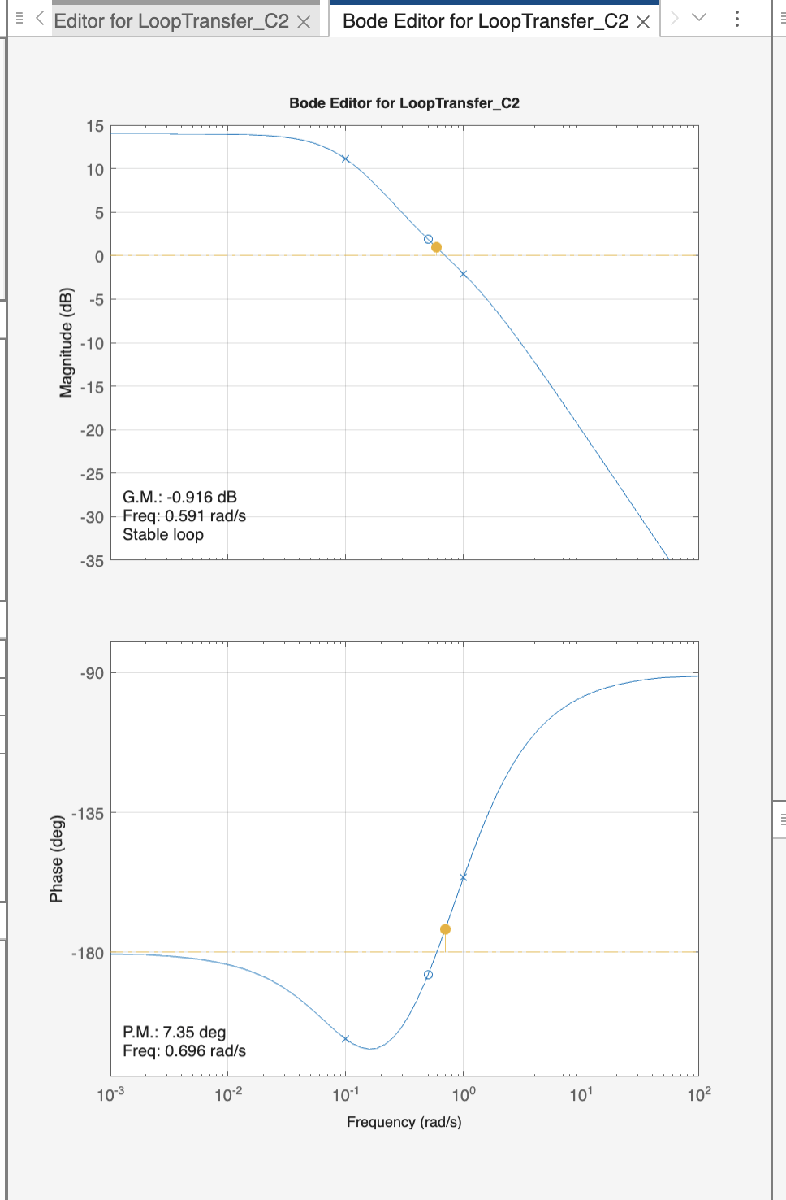

You will find the session data corresponding to the above Figure in the MAT file named `CSD_unstable_2loops_innerLoop_IRL_Bode_gain5.MAT`	

**Remark on the Stability Margins**

**Note**: the gain margin is negative, while the phase margin is positive. Why is the closed loop stable? Let's draw the Nyquist diagram to understand this situation better.

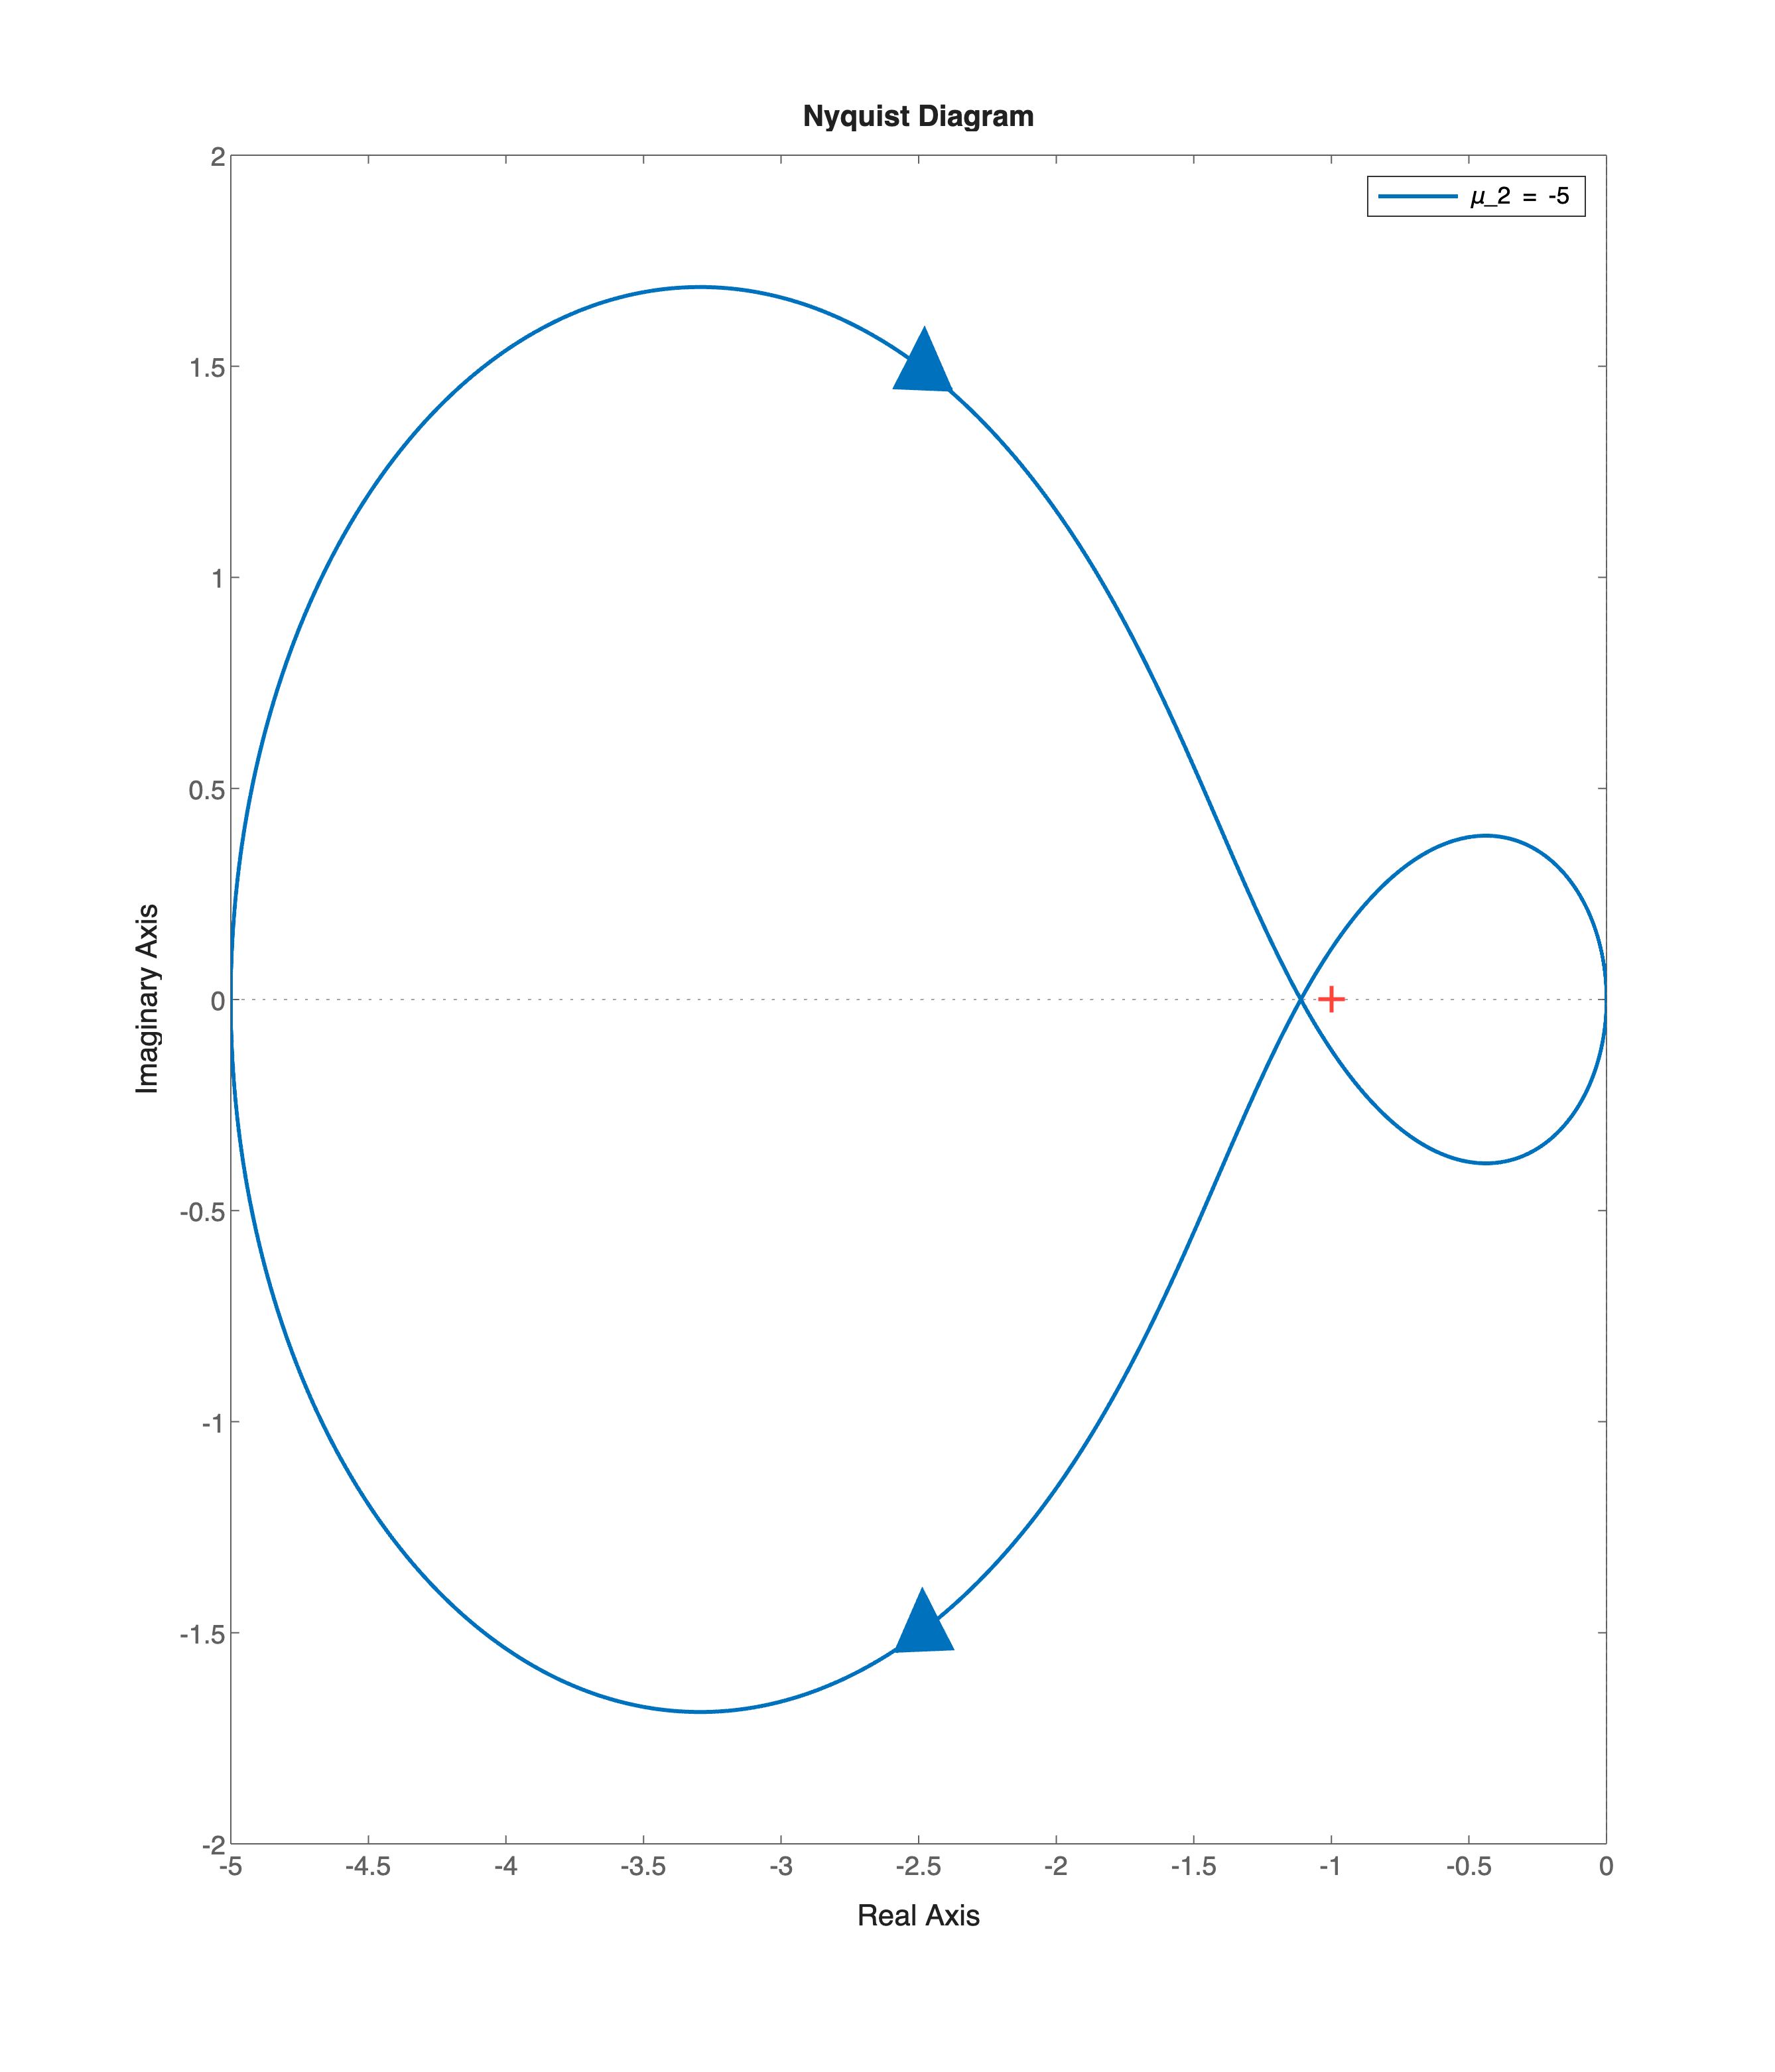

% let's plot the Nyquist diagrams, varying the gain mu_2
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

mu2VAL = -5;
L2s_mu2_5 = mu2VAL*Gs;

L2s_mu2_5.Name = ['\mu_2 = ', num2str(mu2VAL),' '];

np = nyquistplot(ax, L2s_mu2_5, omVALS); 
% -------------
% refer to "NyquistDiagrams_characteristicFeatures.mlx" in Part 09
% -------------
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

Analysing the polar plot, you note $N=+1$; the number of open-loop unstable poles is $n_{p>0} = +1$, thus $N = n_{p>0}$ and the **closed-loop system is asymptotically stable**.

The claim 

"If both the gain and phase margins are positive, then the closed-loop system is asymptotically stable. If either one or both are negative, then the system is unstable. If one of the margins is null, then the closed-loop system is marginally stable"

holds only for an asymptotically stable open-loop system. 

**This is not the case**.

**The Analysis of the Root Locus - Part 2**

In the case $\mu_2=-10$

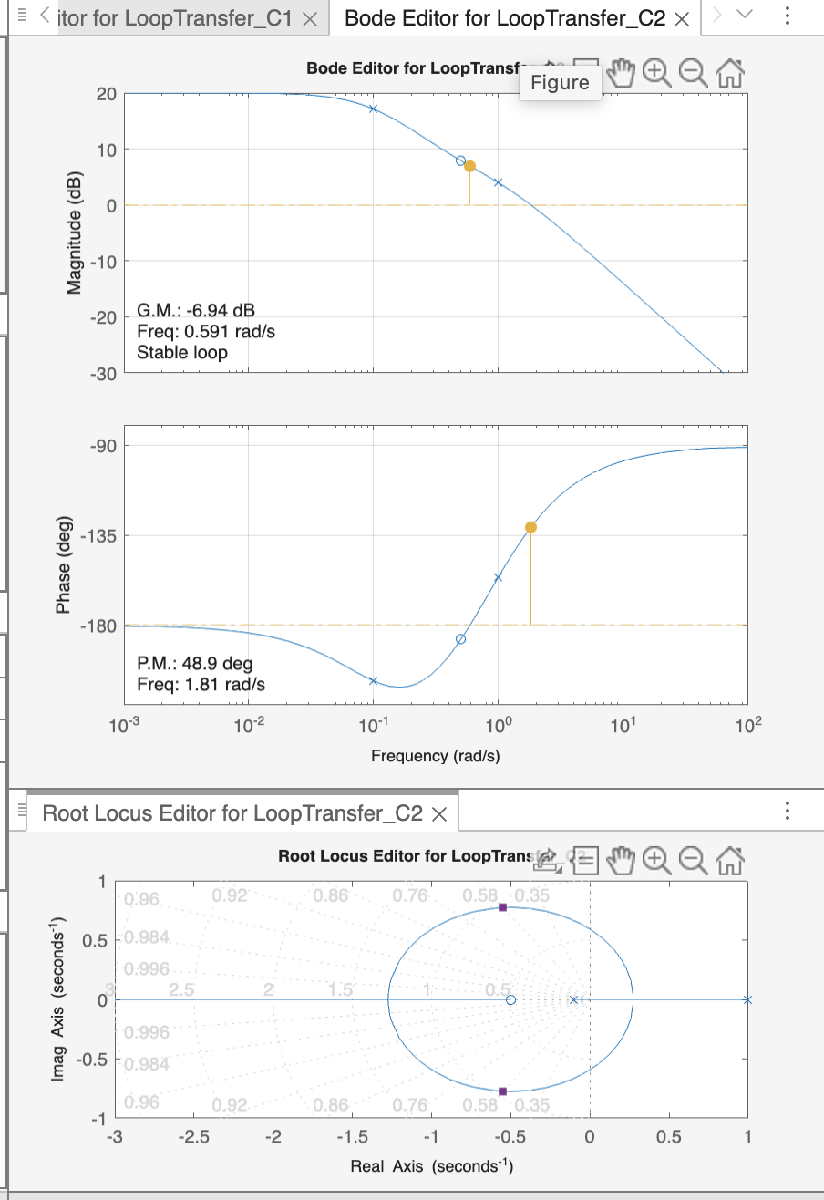

**Note**: we obtained an higher phase margin, thus a better performance, compared to the previous scenario with $\mu_2=-5$.

You will find the session data corresponding to the above Figure in the MAT file named `CSD_unstable_2loops_innerLoop_IRL_Bode_gain10.MAT`	

**Important Remark**

What happens if the gain $\mu_2$ becomes increasingly negative? 

For example, this is the scenario when $\mu_2=-30$

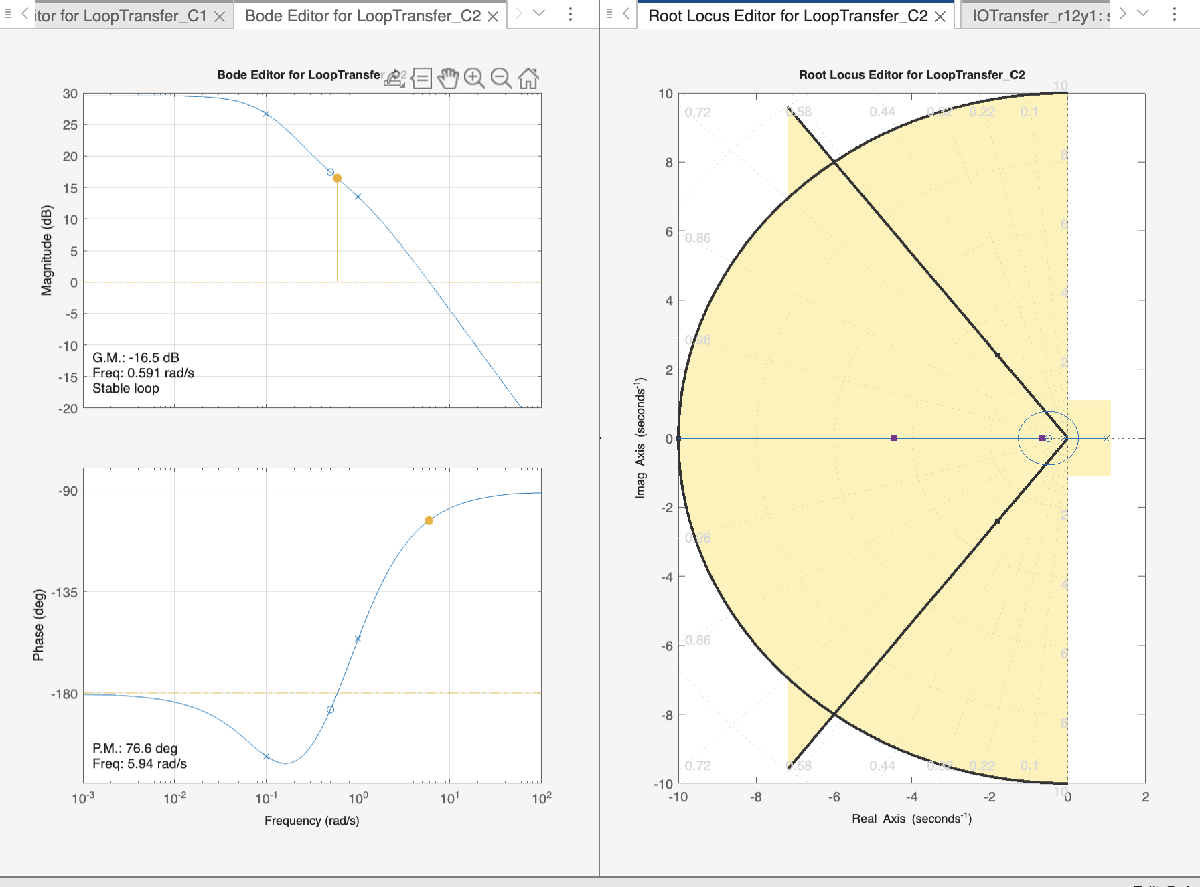

**Note**: with this choice of gain value, we obtain an even better phase margin (higher than the requirement) and a crossover angular frequency $\omega_{c\,2}$ close enough to the required value $\bar \omega_c = 10$ rad/s.

This is the scenario when $\mu_2=-300$

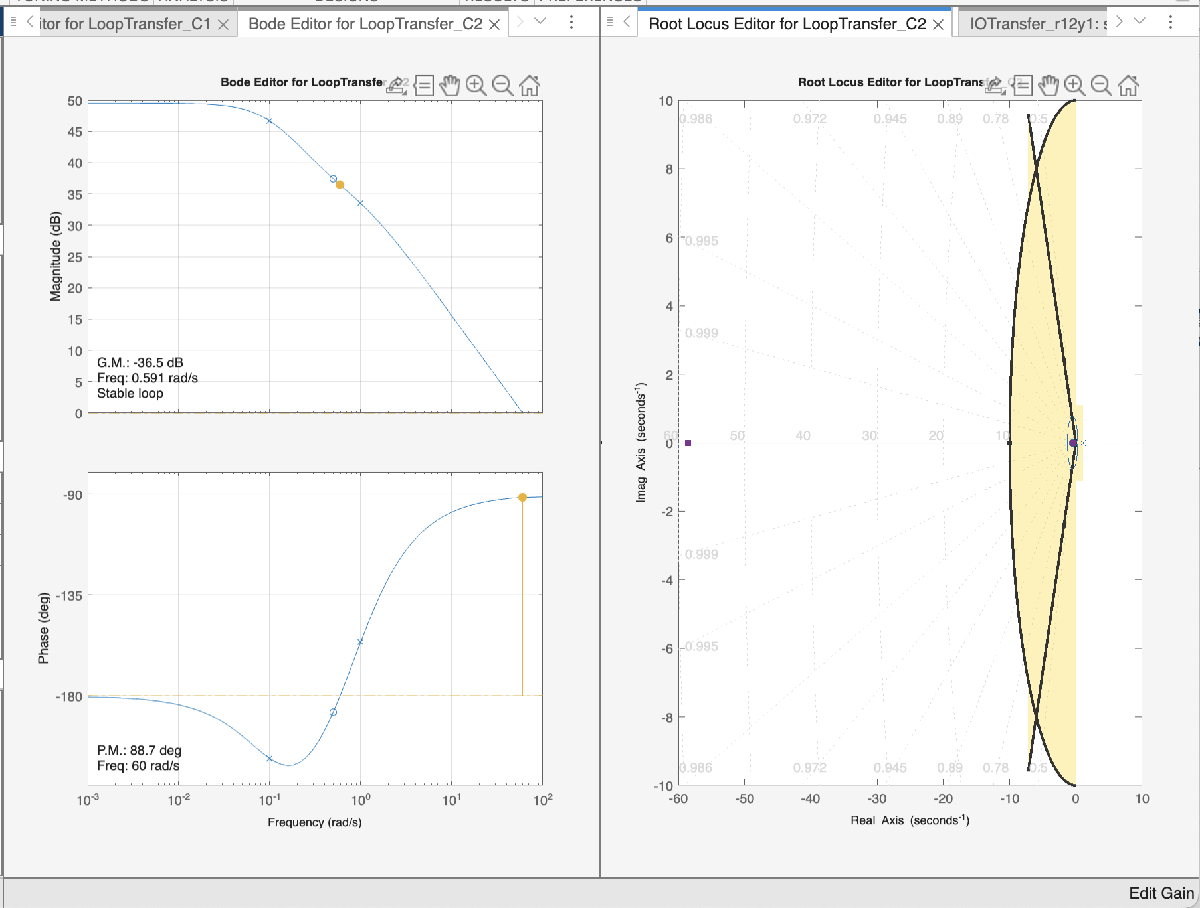

**Note**: with this choice of gain value, we obtain an even better phase margin (higher than the requirement) and a crossover angular frequency $\omega_{c\,2}$ higher than the required value $\bar \omega_c = 10$ rad/s.

**What could be a good choice for the inner controller **$C_2(s)$** to ease the design of the outer loop controller **$C_1(s)$**?**

Generally speaking,  the closer the phase margin and the crossover angular frequency $\omega_{c\,2}$ of the inner open-loop transfer function are to the final requirement targets,  the easier it is to design the outer loop controller.

**Hint**: complete the outer controller design using as inner controller $C_2(s)$ the gain $\mu_2=-30$ or $\mu_2=-300$. Compare the effort and the performance with those of the following solution proposal.

#### Design of the Outer Loop Controller

The proposed solution analyses the scenario with $C_2(s) = -10$:  the inner loop is (of course) asymtotically stable and the corresponding closed-loop transfer function is 


$$F_2(s) = \frac{C_2(s) G(s)}{1+C_2(s)\,G(s)} = \frac{1+2s}{\frac{9}{10}+\frac{11}{10}s+s^2}$$


Let's compute the closed-loop transfer function of the inner loop

% let's define the transfer function builder element
% s=tf('s');
% 
% Gs = (1+2*s)/((1-s)*(1+10*s)); % the unstable process G(s)

C2s = tf(-10); % the stabilising controller

F2s = feedback(C2s*Gs, 1, -1)


**Important** **Remark**: Design requirements do not concern static performance at all. This authorises us to choose a "type $g=0$" controller for $C_1(s)$.

Let's start by selecting simply $C_1(s) = \mu_1 = 1$.

**First** **Step**: Let us analyse the frequency response of the open-loop system $L_1(s)$:


$$L_1(s) = C_1(s) \, F_2(s) = \mu_1 \cdot \frac{1+2s}{\frac{9}{10}+\frac{11}{10}s+s^2}$$


What characteristics does it have? Can the requirements be met with a simple controller? 

muC1 = 1;
C1s = muC1;



F2s =
 
      20 s + 10
  -----------------
  10 s^2 + 11 s + 9
 
Continuous-time transfer function.
Model Properties


Cs = C1s;% *(1+s/25)/s;


Ls = Cs * F2s;

omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ls, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');
figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

margin(Ls)


**Remark**: It is possible to meet the design requirements with a simple proportional controller if the crossover angular frequency $\omega_c$ assumes a value higher than $10$ rad/s. 

For example, considering a frequency $\bar \omega = 15\;\text{rad/s}$ we would get a very good phase margin:


$$\bar \omega = 15\;\text{rad/s} \quad \Longrightarrow \quad \arg L_1(j \bar \omega) = \arg L_1(j 15) \approx -88^{\degree} \quad \Longrightarrow \quad \varphi_m \approx +92^{\degree}$$


Hence, we set $\omega_c = 15\;\text{rad/s}$ and we calculate the value of $\mu_1$that yields this value of the crossover frequency, thus ending the controller design:


$$\left\vert L_1(j \,15)\right\vert = 1 \quad \Longrightarrow \quad 
\hat{\mu}_1 \, \frac{\left\vert 1+j\,30\right\vert}{\left\vert \frac{9}{10}+\frac{11}{10}\cdot j15 -15^2\right\vert} = 1 \quad
\Longrightarrow \quad \hat{\mu}_1  \approx 7.49$$


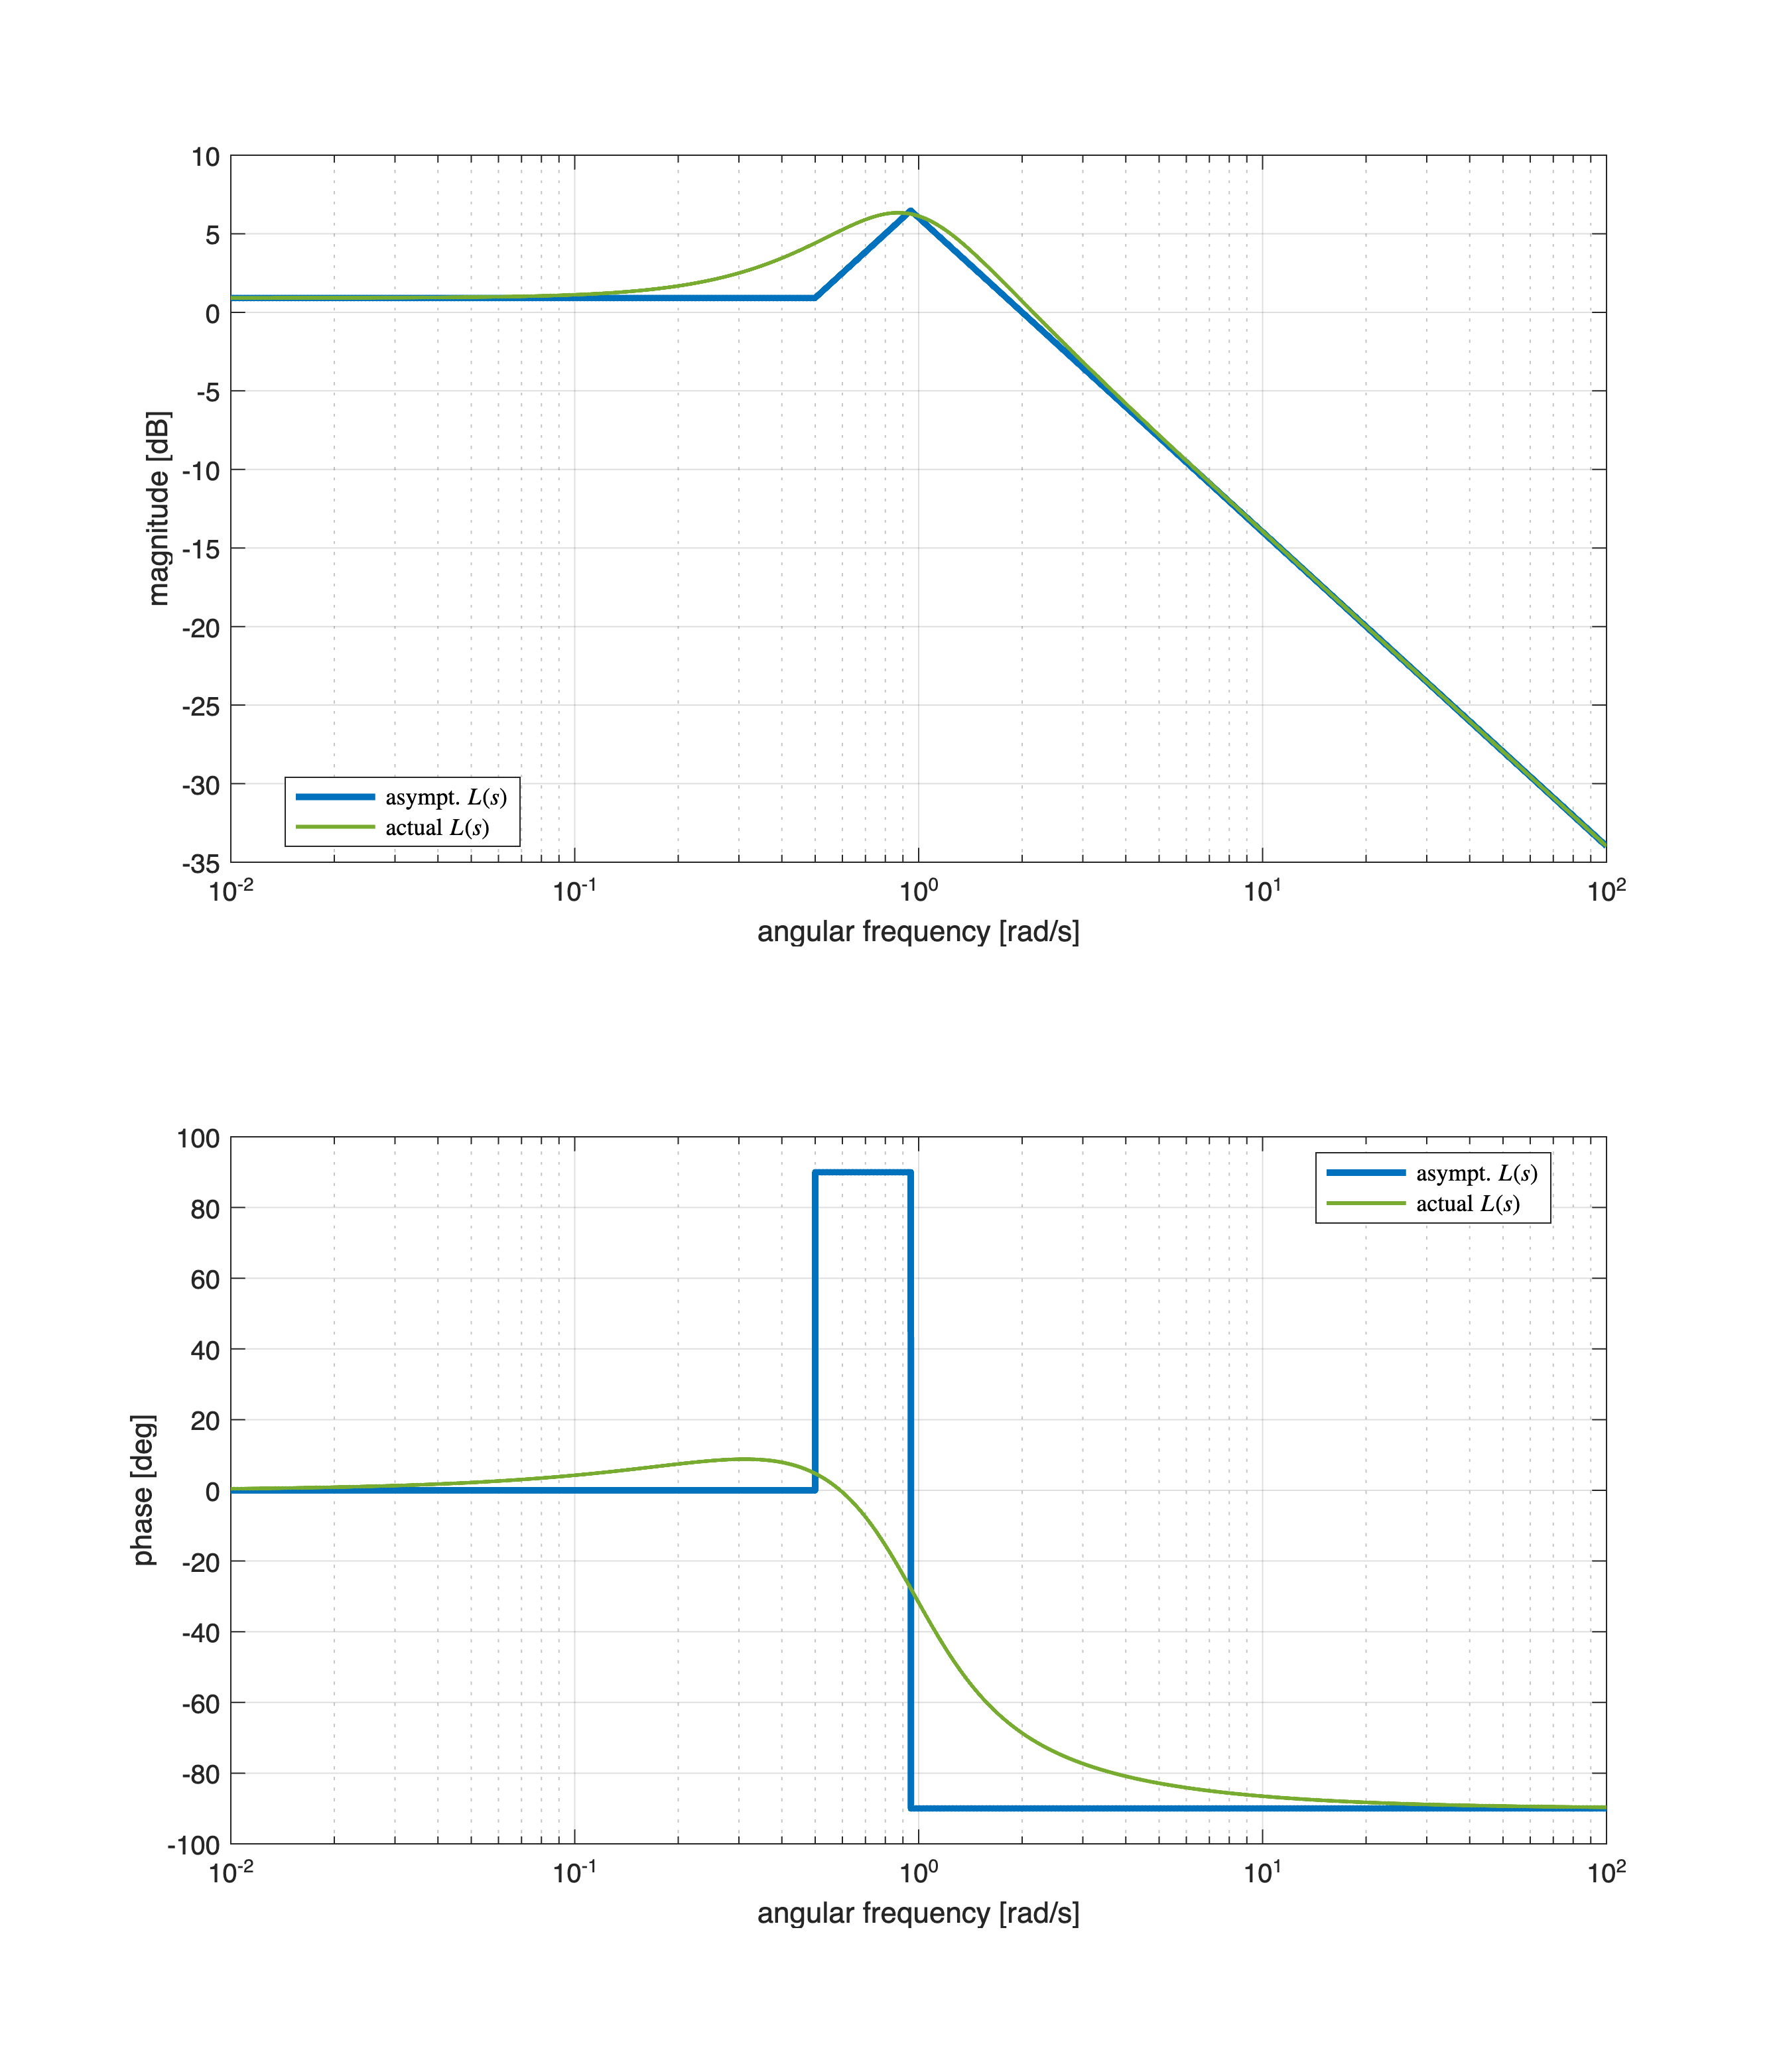

bar_om_c = 15;
hat_mu1 = 1/abs(freqresp(Ls, 15))

C1s = hat_mu1;
Ls1 = C1s * F2s;

omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 

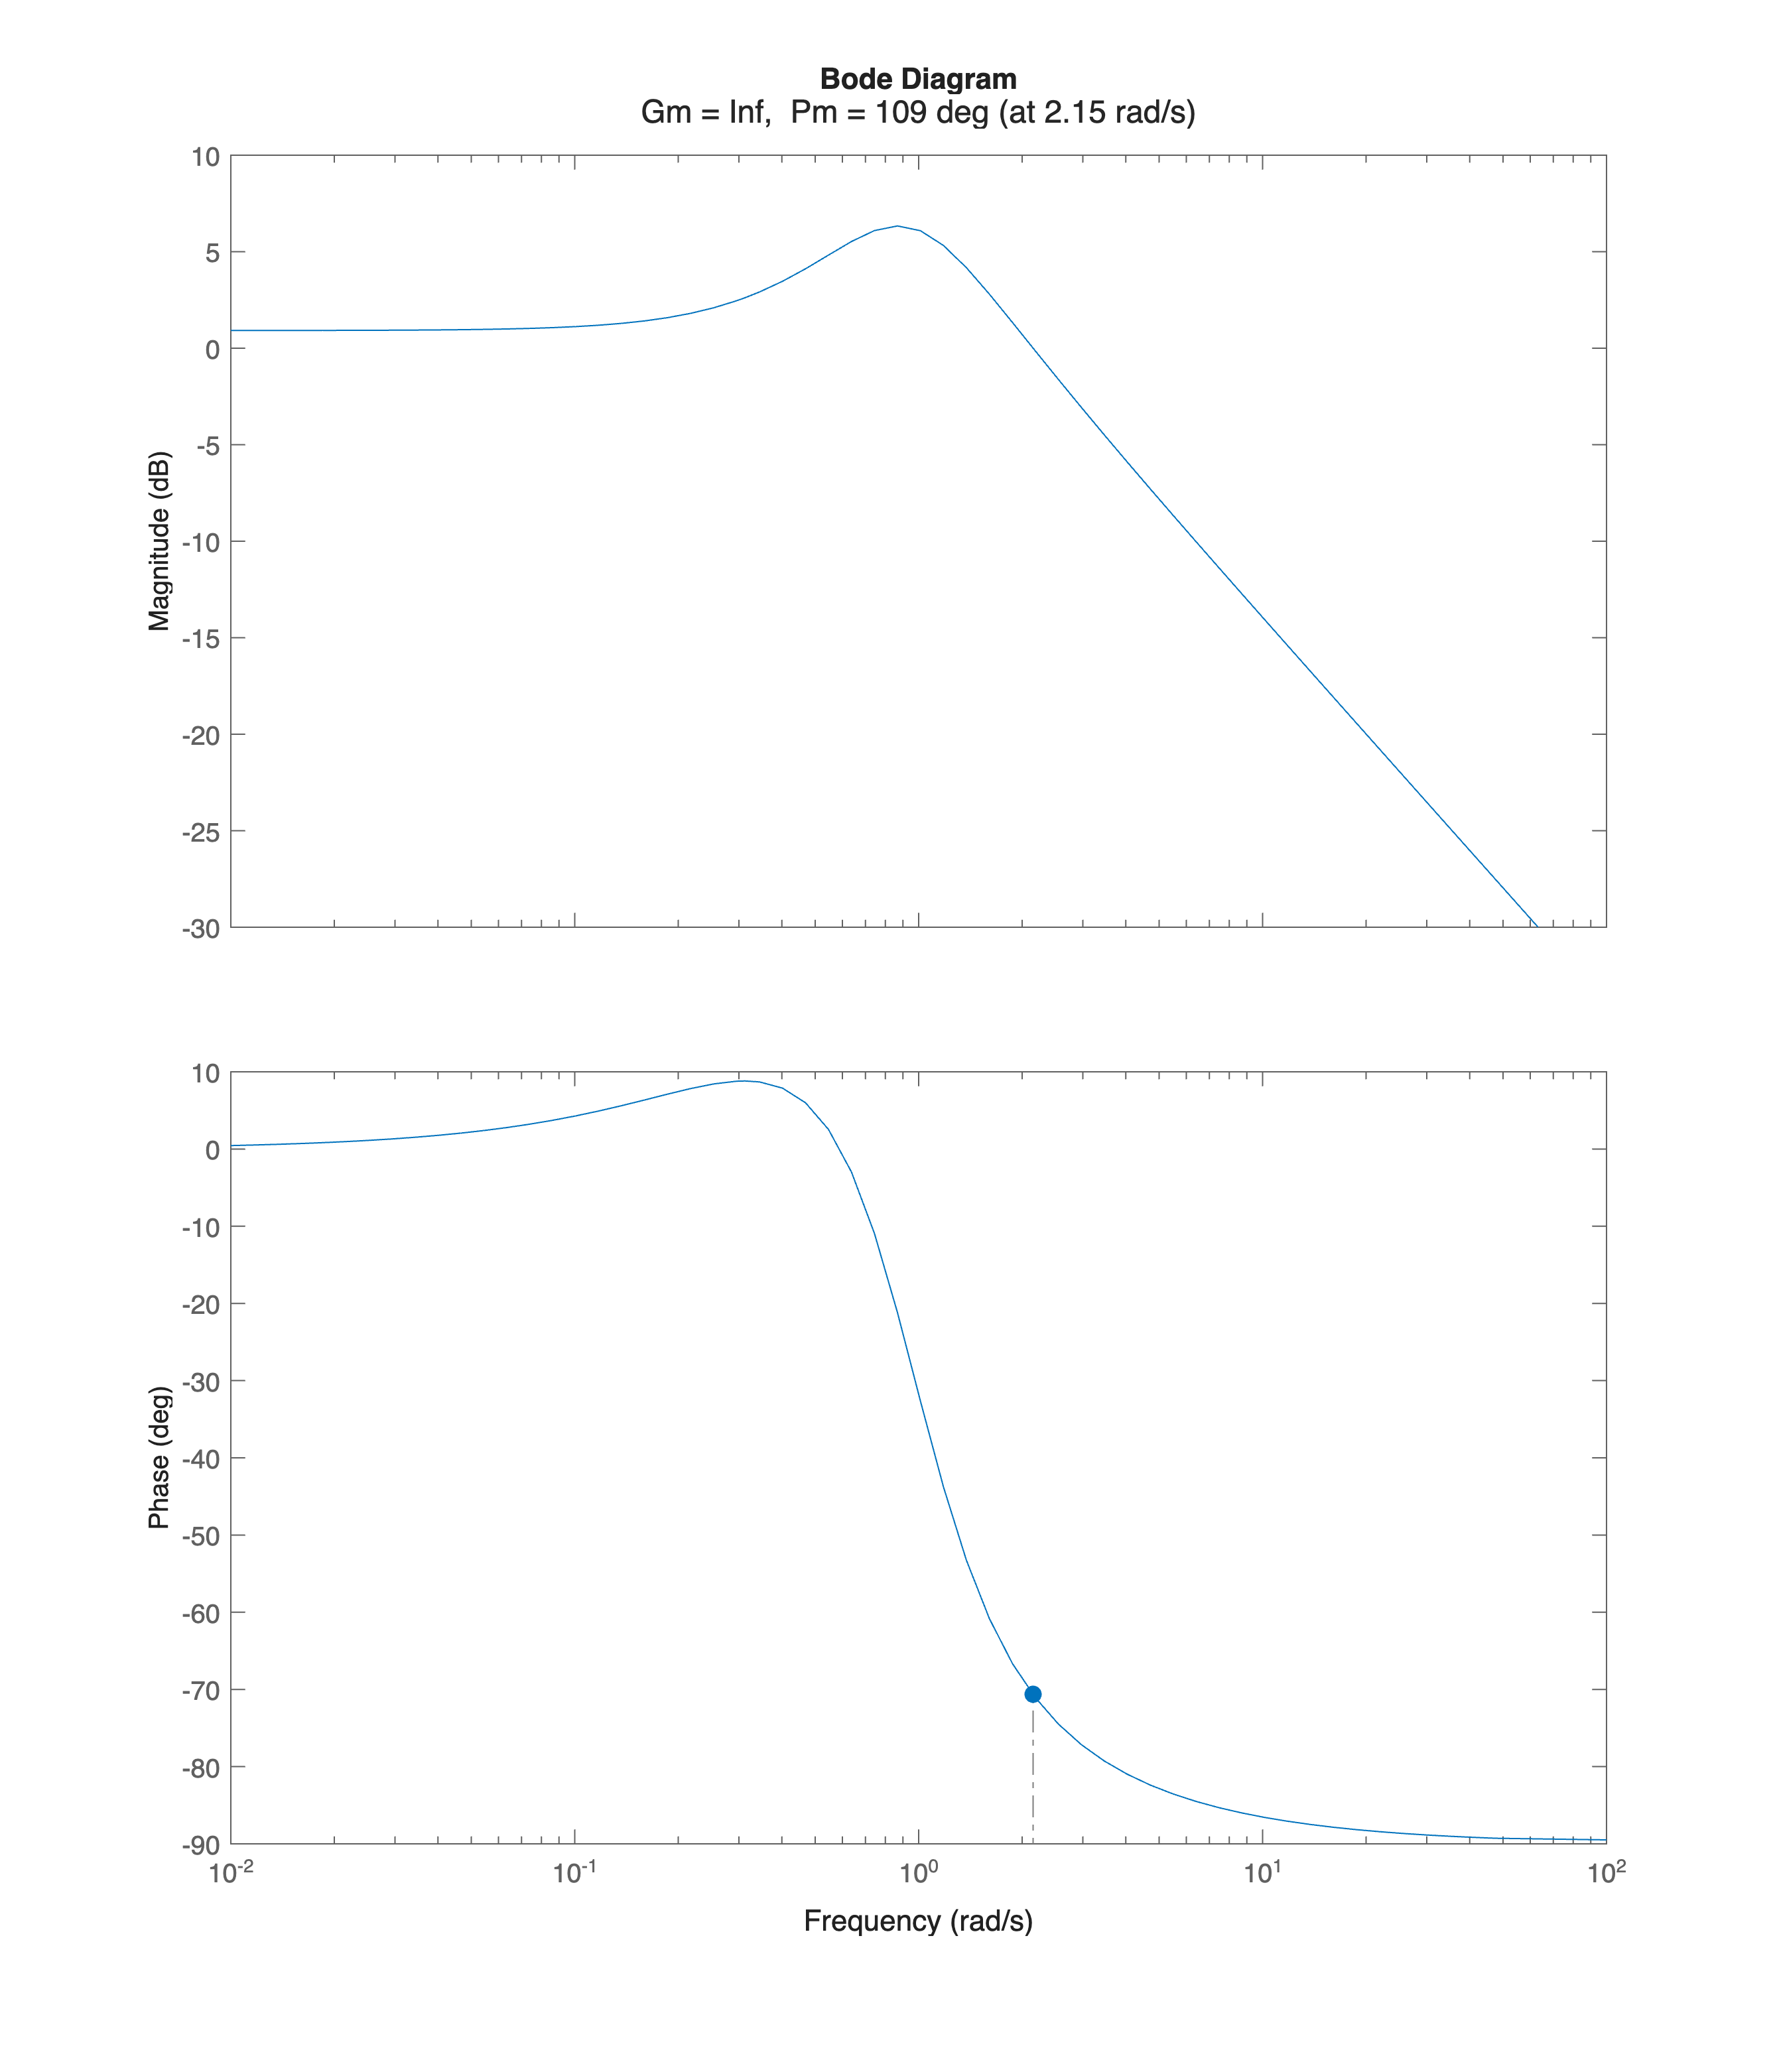

% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better

%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 

hat_mu1 = 7.4861

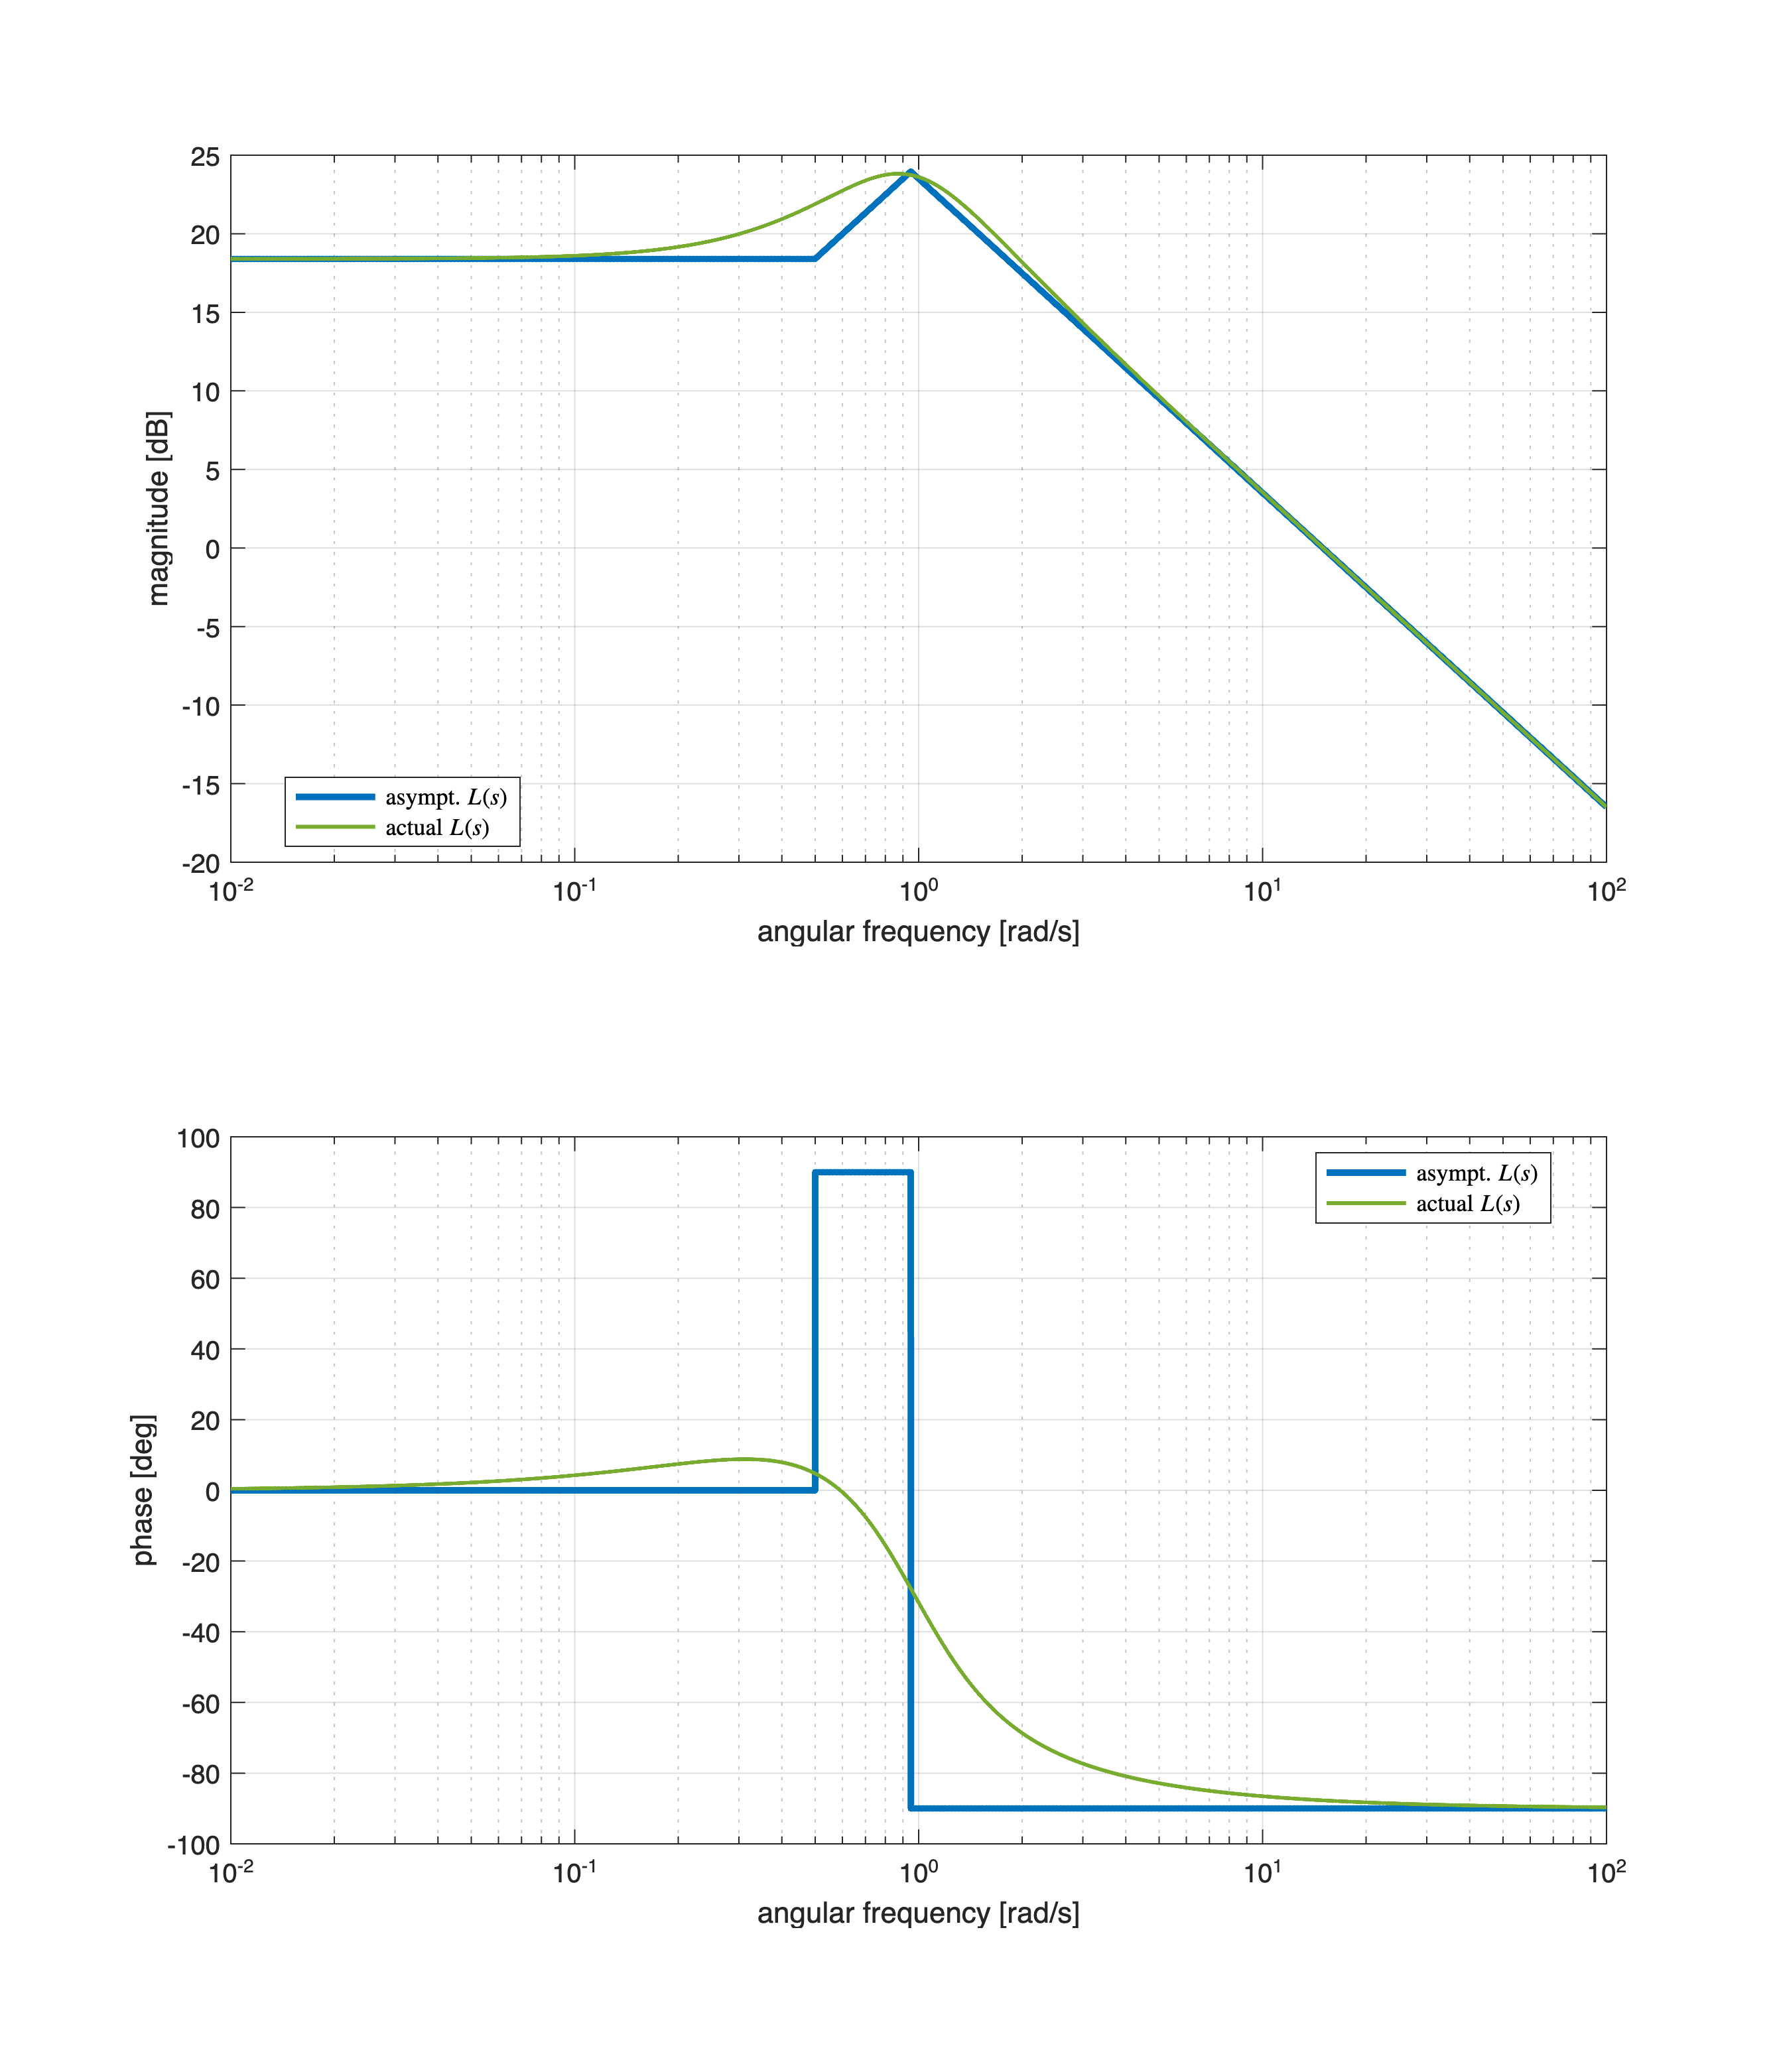

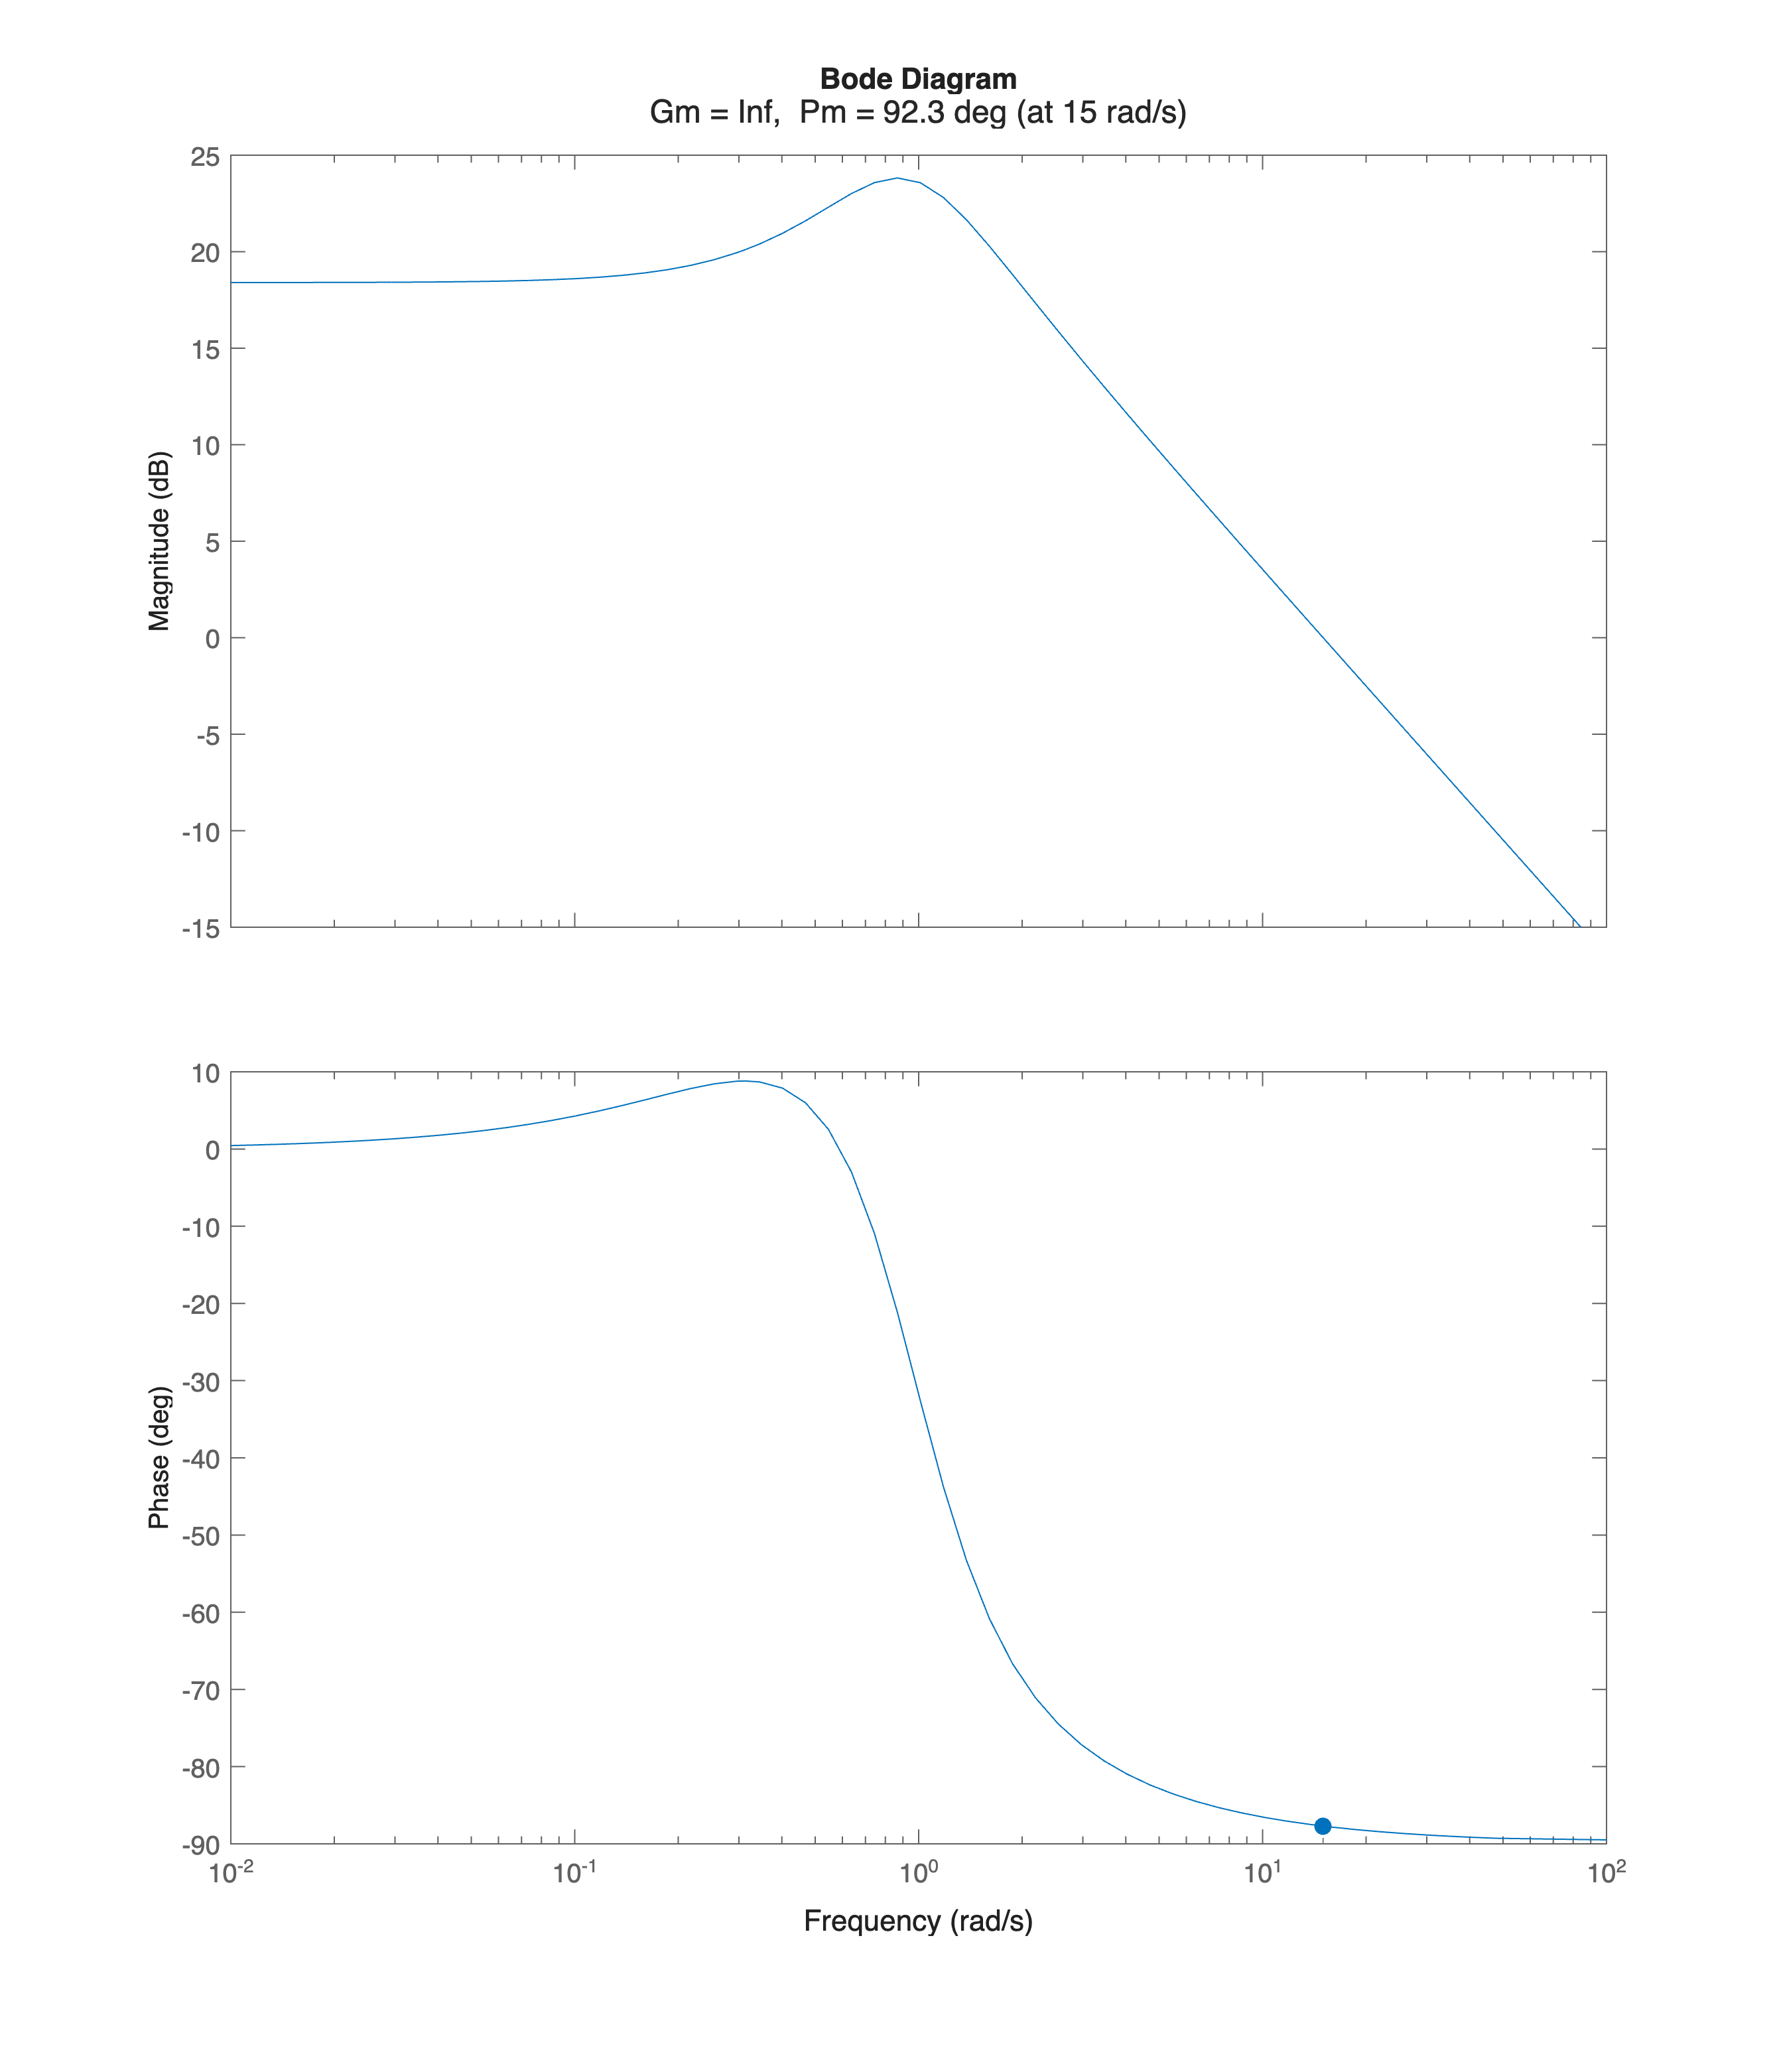

                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ls1, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');


figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
margin(Ls1);

#### Fine Tuning of the Controller

Let's analyse the performance of the just designed controller, using the Control System Designer: set the controller $C_1(s)$ to $C_1(s) = 7.49$

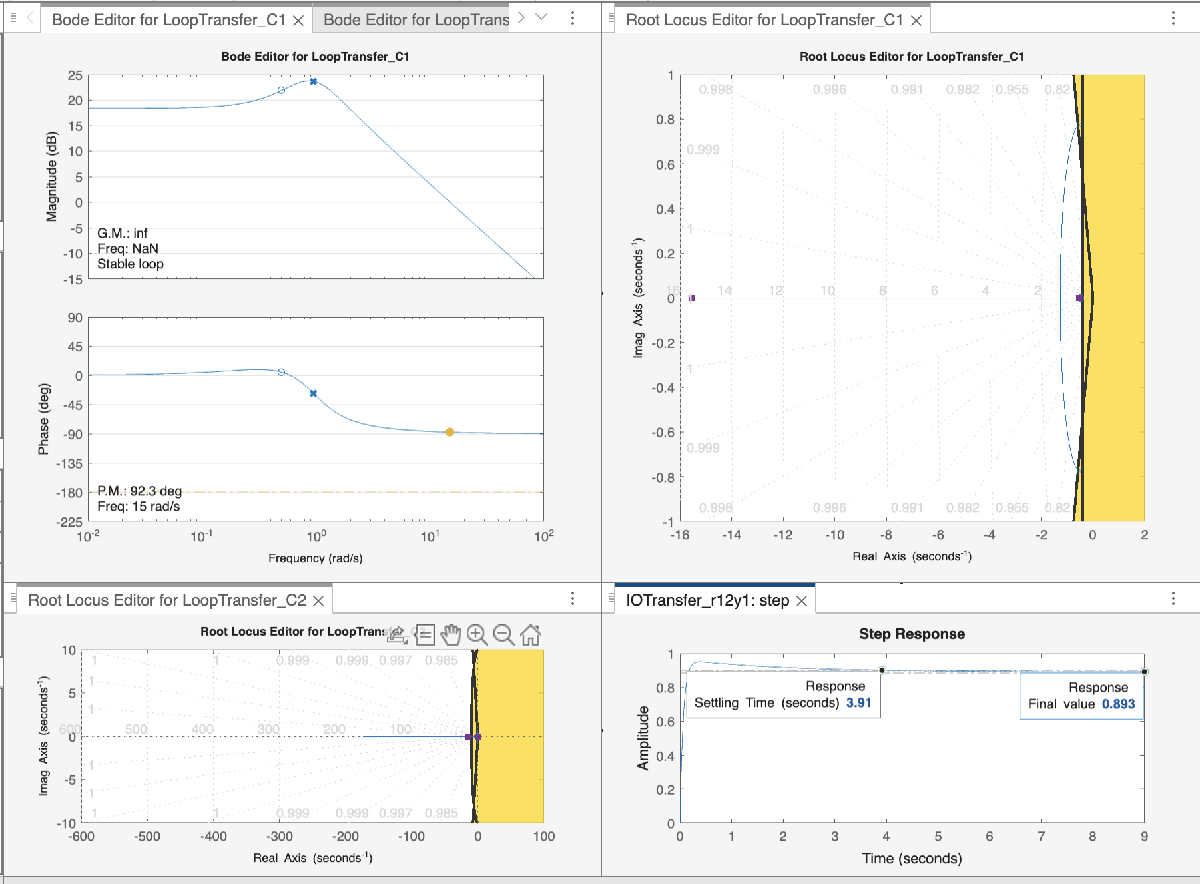

You will find the session data corresponding to the above Figure in the MAT file named `CSD_unstable_2loops_finalmat.MAT`	